## Physical Properties using MTEX

### Luiz F. G. Morales - ScopeM / SGT group - ETH Zürich

luiz.morales@scopem.ethz.ch

based on MTEX development by David Mainprice (Geosciences Montpellier), 

Ralf Hielscher, Helmut Schaeben (Universität Freiberg) and Florian Bachmann

## A potential plan for this lecture

- Let’s start easy – tensor basics, single crystal 2nd rank tensor

- 3rd-rank tensors - Piezoelectricity

- Single crystal elastic 4th rank tensors

- Averaging elastic properties for aggregates – Voigt, Reuss and Hill averaging schemes

## And what is anisotropy?

- Anisotropy is a direction-dependent response of the crystal: the same stimulus applied in different directions (i.e. a tensile stress) leads to different responses (elastic strain);

- The tensors that describe the stimulus-response relation in crystals (elastic, thermal, plastic, electric) are usually anisotropic;

- Single crystals are always anisotropic, and the anisotropy reflects the symmetry of the crystal lattice. For example, while the number of independent components of the elastic tensor is two for an isotropic medium, it is: 

**three **for cubic symmetry;

** five **for hexagonal symmetry 

**nine** for orthogonal symmetry 

## Optical anisotropy of calcite

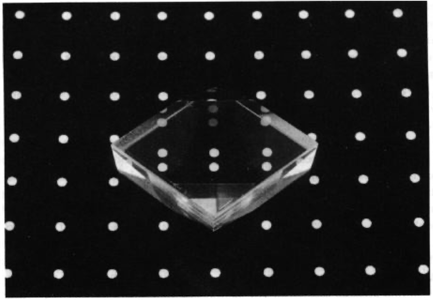

- Calcite optical properties : **2nd Rank Tensor**

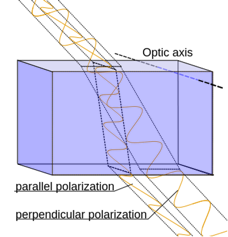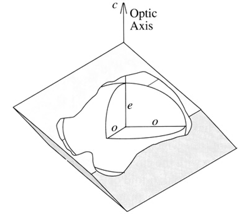

- When light passes through a calcite crystal it splits into two rays, extra ordinary and an ordinary ray. Ordinary ray travels straight and extra ordinary ray is refracted.

## Anisotropy

- If a property is anisotropic in the grains and if the grains have preferred orientation, than the aggregate will also be anisotropic;

- The symmetry of the property is the same as the symmetry of the texture: 

- an aggregate with randomly distributed orientations will have isotropic properties

- Depending on the phases evolved and the type of deformation, anisotropy may have axial, orthorrhombic or monoclinic symmetry;

## What is a tensor?

- Tensors are mathematical objects used to describe physical properties, just like scalars and vectors;

- Tensors are merely a generalisation of scalars and vectors; a scalar is a zero rank tensor, and a vector is a first rank tensor;

- The rank (or order) of a tensor is defined by the number of directions required to describe it;

- For example, properties that require one direction (first rank) can be fully described by a 3×1 column vector, and properties that require two directions (second rank tensors), can be described by 9 numbers, as a 3×3 matrix;

## Tensor ranking of physical properties

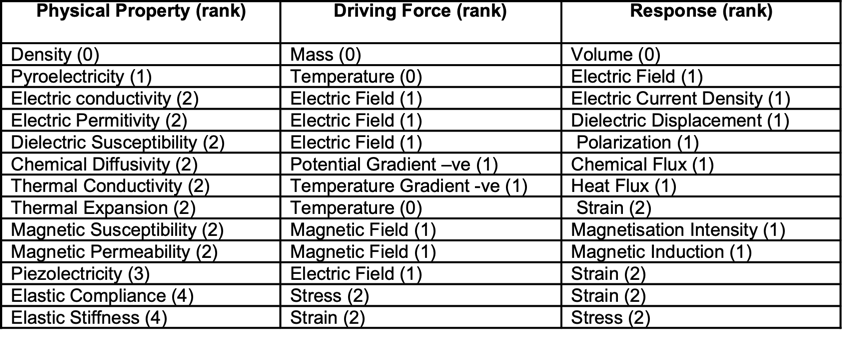

## Second-rank tensors

- Typically relates 2 vectors – for example thermal conductivity :  applied vector (negative) temperature gradient  and resulting vector heat flow density, exception thermal expansion relates temperature (0) and strain (2).

- 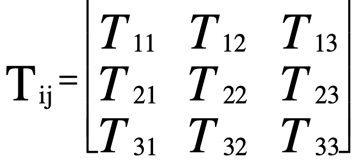

- The generic 2nd rank tensor **T** is the relation between an applied vector** p** and resultant vector **q**. We can write relation between **p** and **q**as a tensor equation

**                                    p**= **T q**  or  pi = Tij qj  (i=1,2,3 ; j=1,2,3)

- In general the vectors **p** and **q **are not parallel.

## **Radius-normal property and melting wax experiment**

- Consider a red hot arrow touching the second order prism plane of a single crystal of quartz and creating a point heat source. A (negative) thermal gradient will result in heat flow away from the hot heat source (arrow tip) to the colder regions of the crystal. As the thermal resistivity (reciprocal of thermal conductivity) varies with direction the heat flow will not be equal in all radial directions, i.e. heat flow is anisotropic.

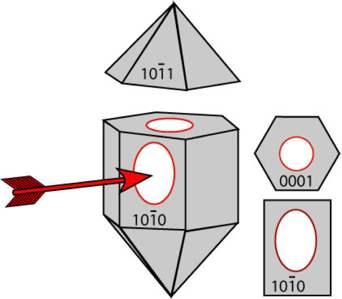

## **How** **to** **define**** a ****tensor**** in MTEX – thermal ****conductivity quartz**

close all
clear all

cs_tensor_quartz = crystalSymmetry.load('quartz')

 
cs_tensor_quartz = crystalSymmetry
 
  mineral        : Quartz            
  symmetry       : 321               
  elements       : 6                 
  a, b, c        : 4.9, 4.9, 5.4     
  reference frame: X||a*, Y||b, Z||c*
 


%% Define thermal conductivity tensor coefficients (in W/m/K unit)

M = [[10.5 0.00 0.00];[0.00 6.20 0.00];[0.00 0.00 6.20]]

M =    10.5000         0         0
         0    6.2000         0
         0         0    6.2000



%%  Define the thermal conductivity tensor

k = tensor (M, 'name', 'thermal_conductivity','rank',2, 'unit', ...
    'W_1/m_1/K',cs_tensor_quartz)

 
k = tensor (Quartz)
  unit: W_1/m_1/K
  rank: 2 (3 x 3)
 
 10.5    0    0
    0  6.2    0
    0    0  6.2


## **How** **to** **represent** **tensor** **properties**** in MTEX – thermal ****conductivity**

%% Plot thermal conductivity tensor

plot (k, 'complete','lower','contourf')
mtexColorbar

% annotate with single crystal pole to planes

h = Miller({0,0,0,1},{1,1,-2,0},{2,-1,-1,0},{1,0,-1,0},{1,0,-1,1},...
    {0,1,-1,1},{1,0,-1,2},{0,1,-1,2},cs_tensor_quartz);
h_s=symmetrise(h)

 
h_s = Miller (Quartz)
 size: 6 x 8
 
  show Miller
 


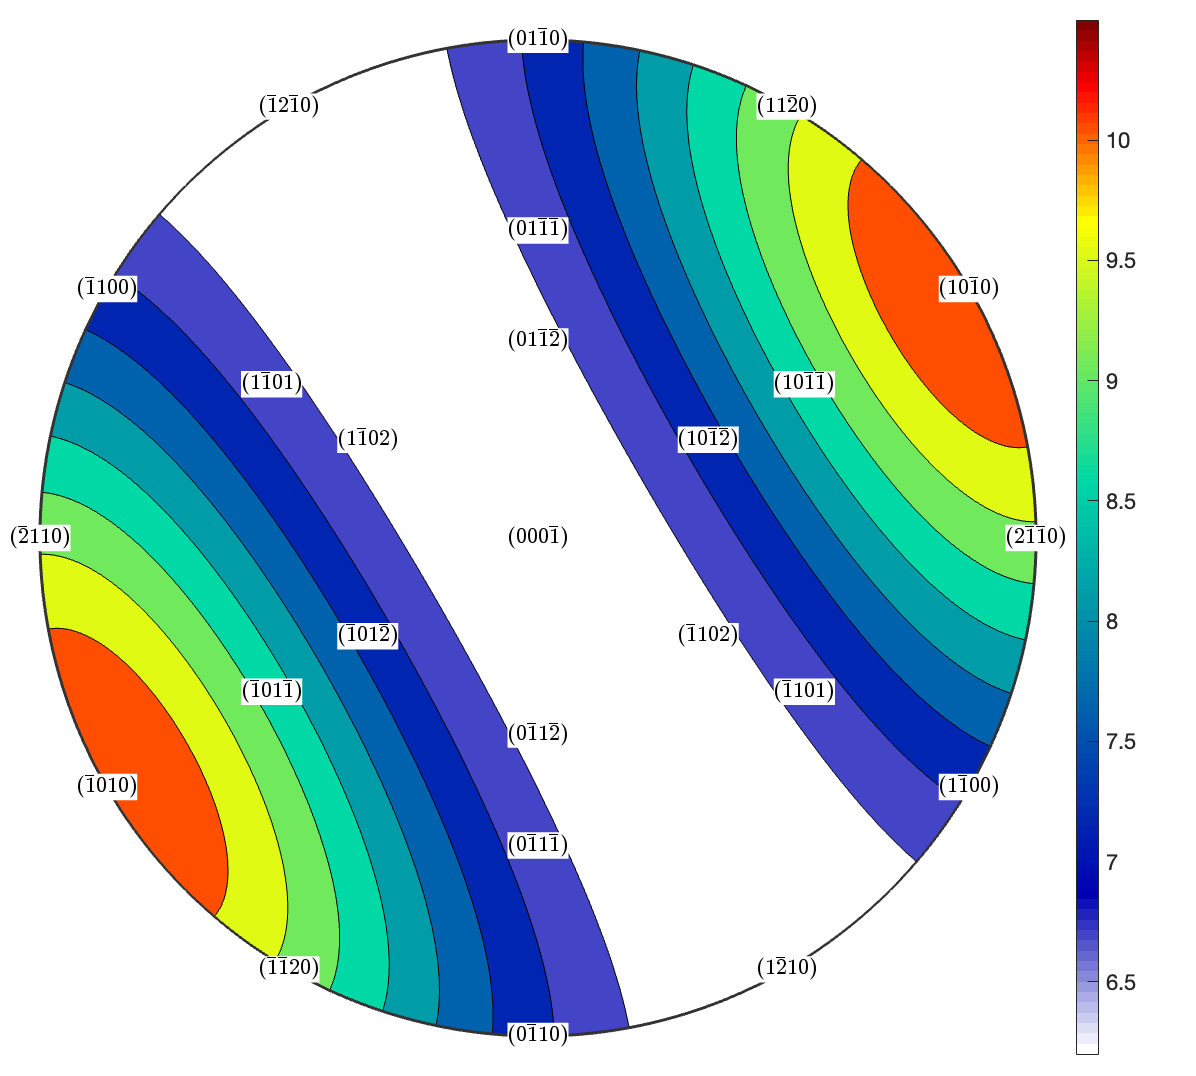

hold on
text(h_s,'labeled','backgroundColor','w','grid','upper','doNotDraw')
hold off

## **A ****very** **important** **property** **of** **tensors**

- One of the fundamental properties of tensors of physical properties is that the magnitude of the physical property is invariant with the rotation of the coordinate reference frame, which is attached to the crystal;

- A crystal may rotate in sample reference frame (which is an external reference frame), but the tensor reference frame is related to the crystal structure and rotates with the crystal, like a rigid rotation

- What happens if we rotate the tensor previously defined?

## Rotate tensor and replot

%% Let's rotate the tensor and plot it again

% define a rotation

g = rotation.byEuler(30*degree,60*degree,90*degree)

 
g = rotation
 
  Bunge Euler angles in degree
  phi1  Phi phi2
    30   60   90
 



% rotate tensor

k_rot = rotate (k,g)

 
k_rot = tensor (Quartz)
  unit: W_1/m_1/K
  rank: 2 (3 x 3)
 
  6.469 -0.465 -0.931
 -0.465  7.006  1.613
 -0.931  1.613  9.425



% plot rotated tensor 

close all
plot (k_rot, 'complete','lower','contourf','minmax')
mtexColorbar
h_s_new=g*h

 
h_s_new = Miller (Quartz)
 size: 1 x 8
        h       k       i       l
   0.6821 -0.6821       0     0.5
    -1.25    0.25       1  1.6493
    -0.25    1.25      -1  1.6493
     -0.5     0.5       0  1.0996
   0.1821 -0.1821       0  1.5996
  -0.0679 -0.9321       1  1.0498
   0.8642 -0.8642       0  2.0996
   0.6142 -1.6142       1  1.5498


h_s_new=round(h_s_new)

 
h_s_new = Miller (Quartz)
 size: 1 x 8
   h   k   i   l
  11 -11   0   8
  -9   2   7  12
  -2   9  -7  12
  -5   5   0  11
   1  -1   0   9
  -1 -10  11  11
   5  -5   0  12
   3  -8   5   8


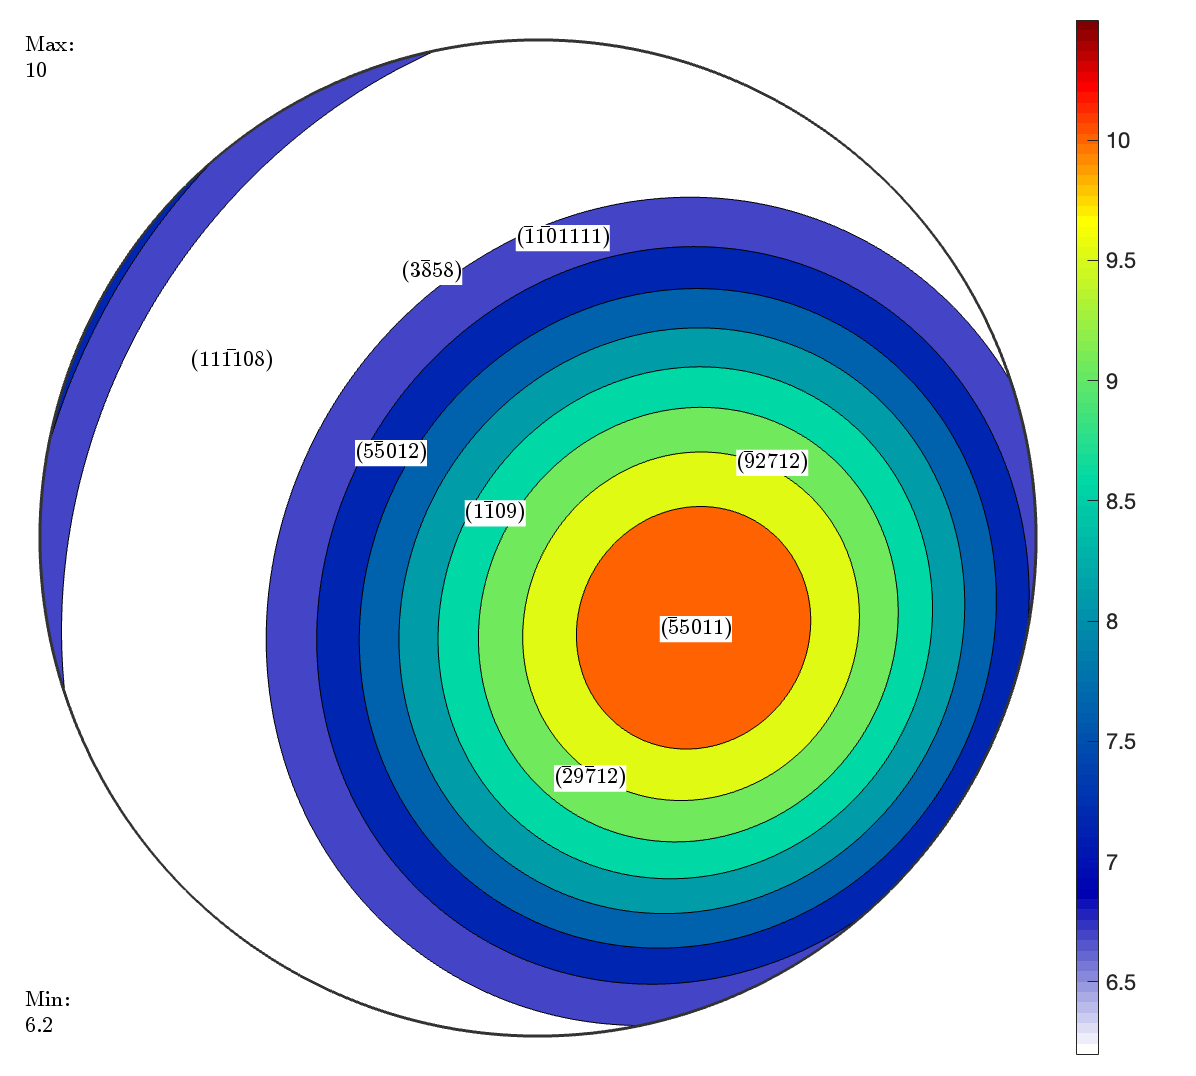



% annotate with single crystal pole to planes
hold on
text(h_s_new,'labeled','backgroundColor','w','grid','upper','doNotDraw')
hold off

## The quadric representation for 2nd-rank tensors

- A common way to represent second-rank tensors is via a second degree surface (also named a "quadric");

-  The quadric may be an ellipsoid or a hyperboloid. 

- Most common second-rank tensors are symmetric (Tij = Tji). In that case, and if the 3 main coefficients are positive, then the property can be represented by an ellipsoid with 1/√T1, 1/√T2 and 1/√T3, 

- That is the case of thermal conductivity, electric polarization and optical properties

- In MTEX, this elipsoid can be plotted with the command 'surf'

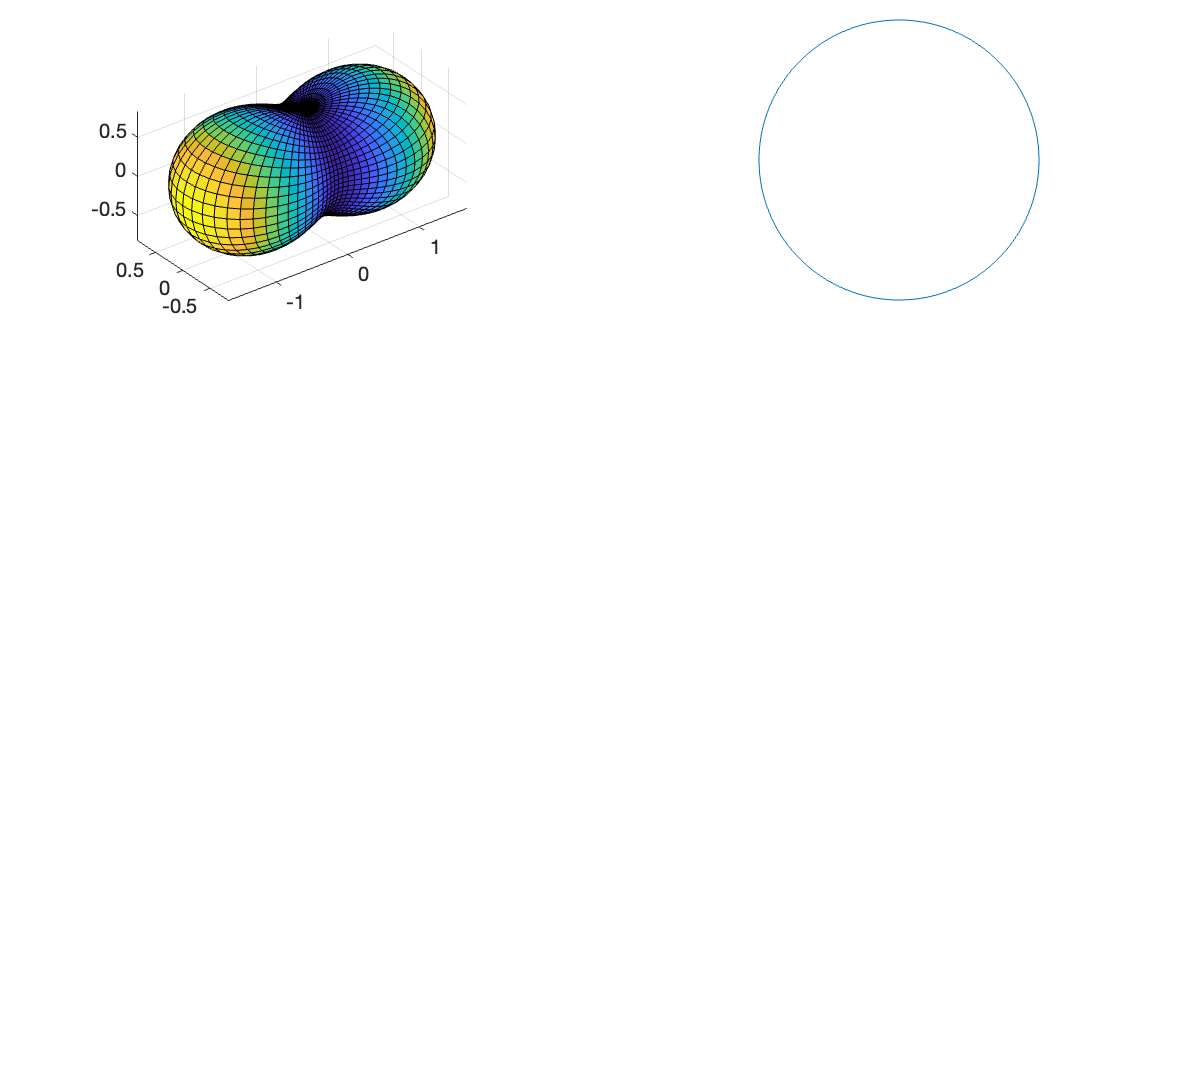

%% Plot thermal conductivity as 3D surface

% plot quadric representation for thermal conductivity

newMtexFigure('layout',[1,2]) % figure layout: one line, two columns
surf(k.directionalMagnitude)

% plot section along X on the surface
nextAxis 
plotSection(k.directionalMagnitude,vector3d.X)
drawNow(gcm)

- In this example, the section is parallel to X vector of the elipsoid.

-  Note that the quadric representation can be also rotated on the fly for the visualization in different directions.

## The hyperboloid representation for 2nd-rank tensors

- When one of the main diagonal coefficients of the tensor is negative, the surface is a hyperboloid of one sheet (e.g. thermal expansion of plagioclase);

- If two values are negative, then the surface will be a hyperboloid of two sheets (e.g. thermal expansion of calcite - contraction on the basal plane)

- If all three values are negative, as in the case of magnetic suceptibility of some minerals, the surface is a imaginary ellipsoid

## The example of thermal expansion of calcite

%% Define tensor reference frame

cs_tensor_cal = crystalSymmetry('321', [4.99 4.99 17.064], 'X||a', ...
    'Y||b*', 'Z||c','mineral', 'Calcite', 'color', 'light blue');

%% Define thermal expansion coefficient

%  Coefficients from Fei 1995 AGU Bookshelf Series Mineral 
%  Physics vol.2 Chapter 6 Thermal expansion in x 10-6 1/K units

M_cal = [[-3.2E-6 0.00 0.00];[0.00 -3.2E-6 0.00];[0.00 0.00 13.3E-6]]

M_cal = 1.0e-04 *

   -0.0320         0         0
         0   -0.0320         0
         0         0    0.1330



%%  Define the thermal expansion tensor

k_cal = tensor (M_cal, 'name', 'thermal_expansion','rank',2, 'unit', ...
    '[K^-1]',cs_tensor_cal)

 
k_cal = tensor (Calcite)
  unit: [K^-1]   
  rank: 2 (3 x 3)
 
 *10^-6
 -3.2    0    0
    0 -3.2    0
    0    0 13.3



% plot the thermal expansion tensor 

figure (1)
plot (k_cal, 'complete','lower','contourf')
mtexColorbar
h = Miller({1,0,-1,0},{1,1,-2,0},{1,0,-1,4},{0,1,-1,0},{0,0,0,1},cs_tensor_cal);
h_s=symmetrise(h)

 
h_s = Miller (Calcite)
 size: 6 x 5
 
  show Miller
 


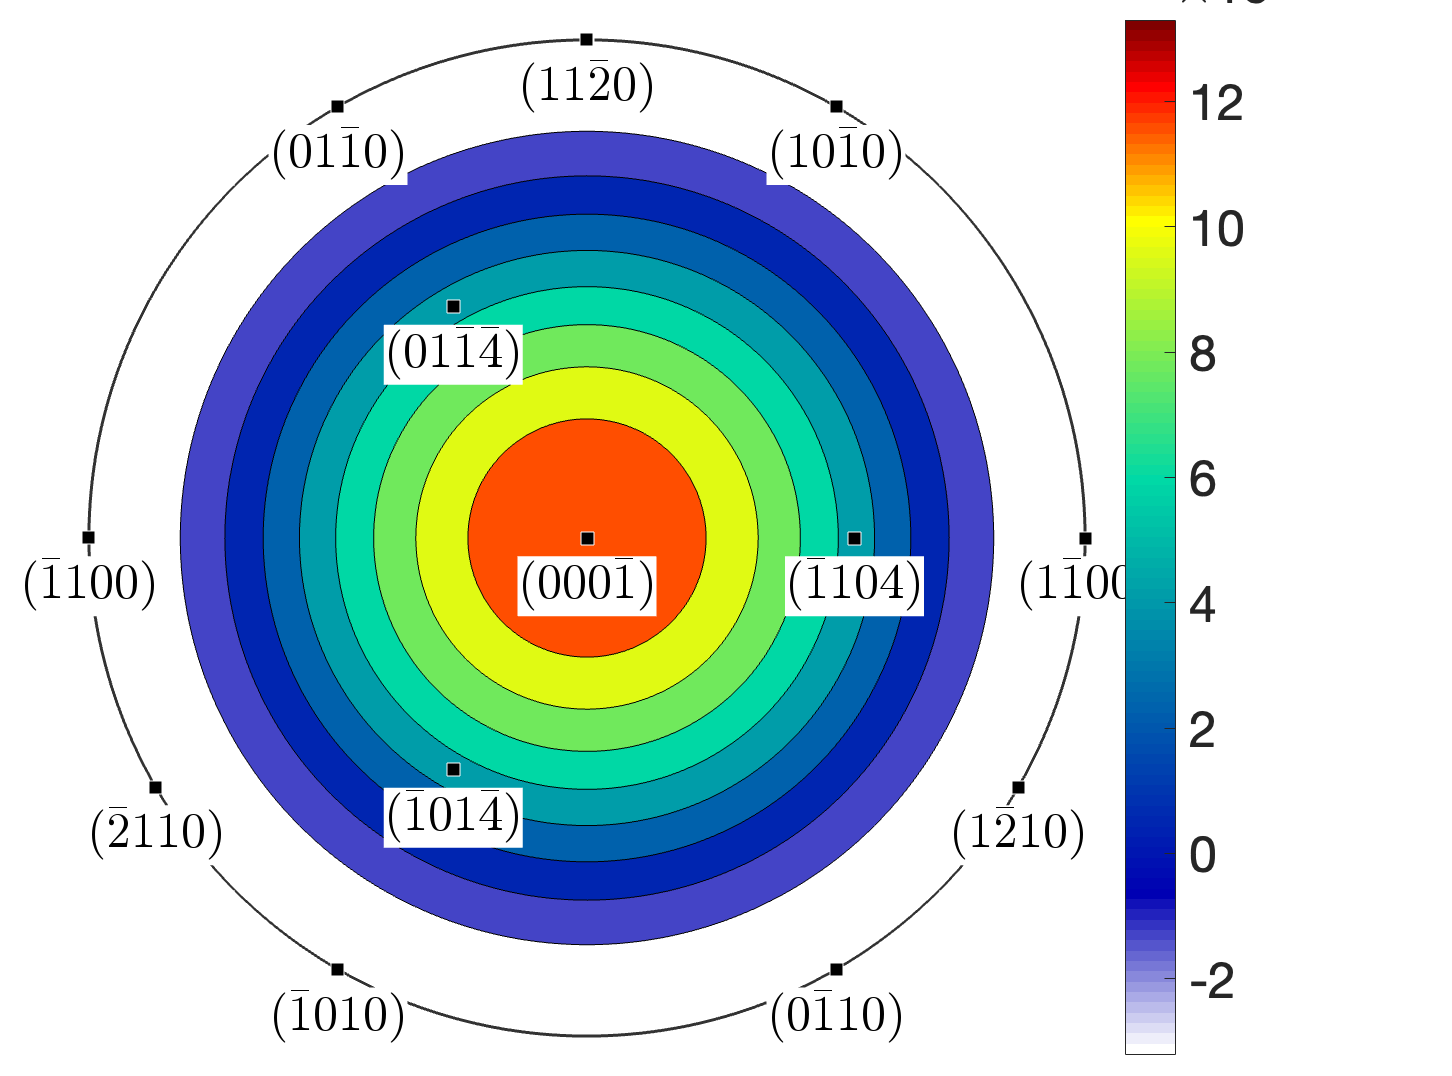

hold on
annotate(h_s,'labeled','backgroundColor','w','grid','upper','doNotDraw')
hold off
drawNow(gcm,'figSize','large')

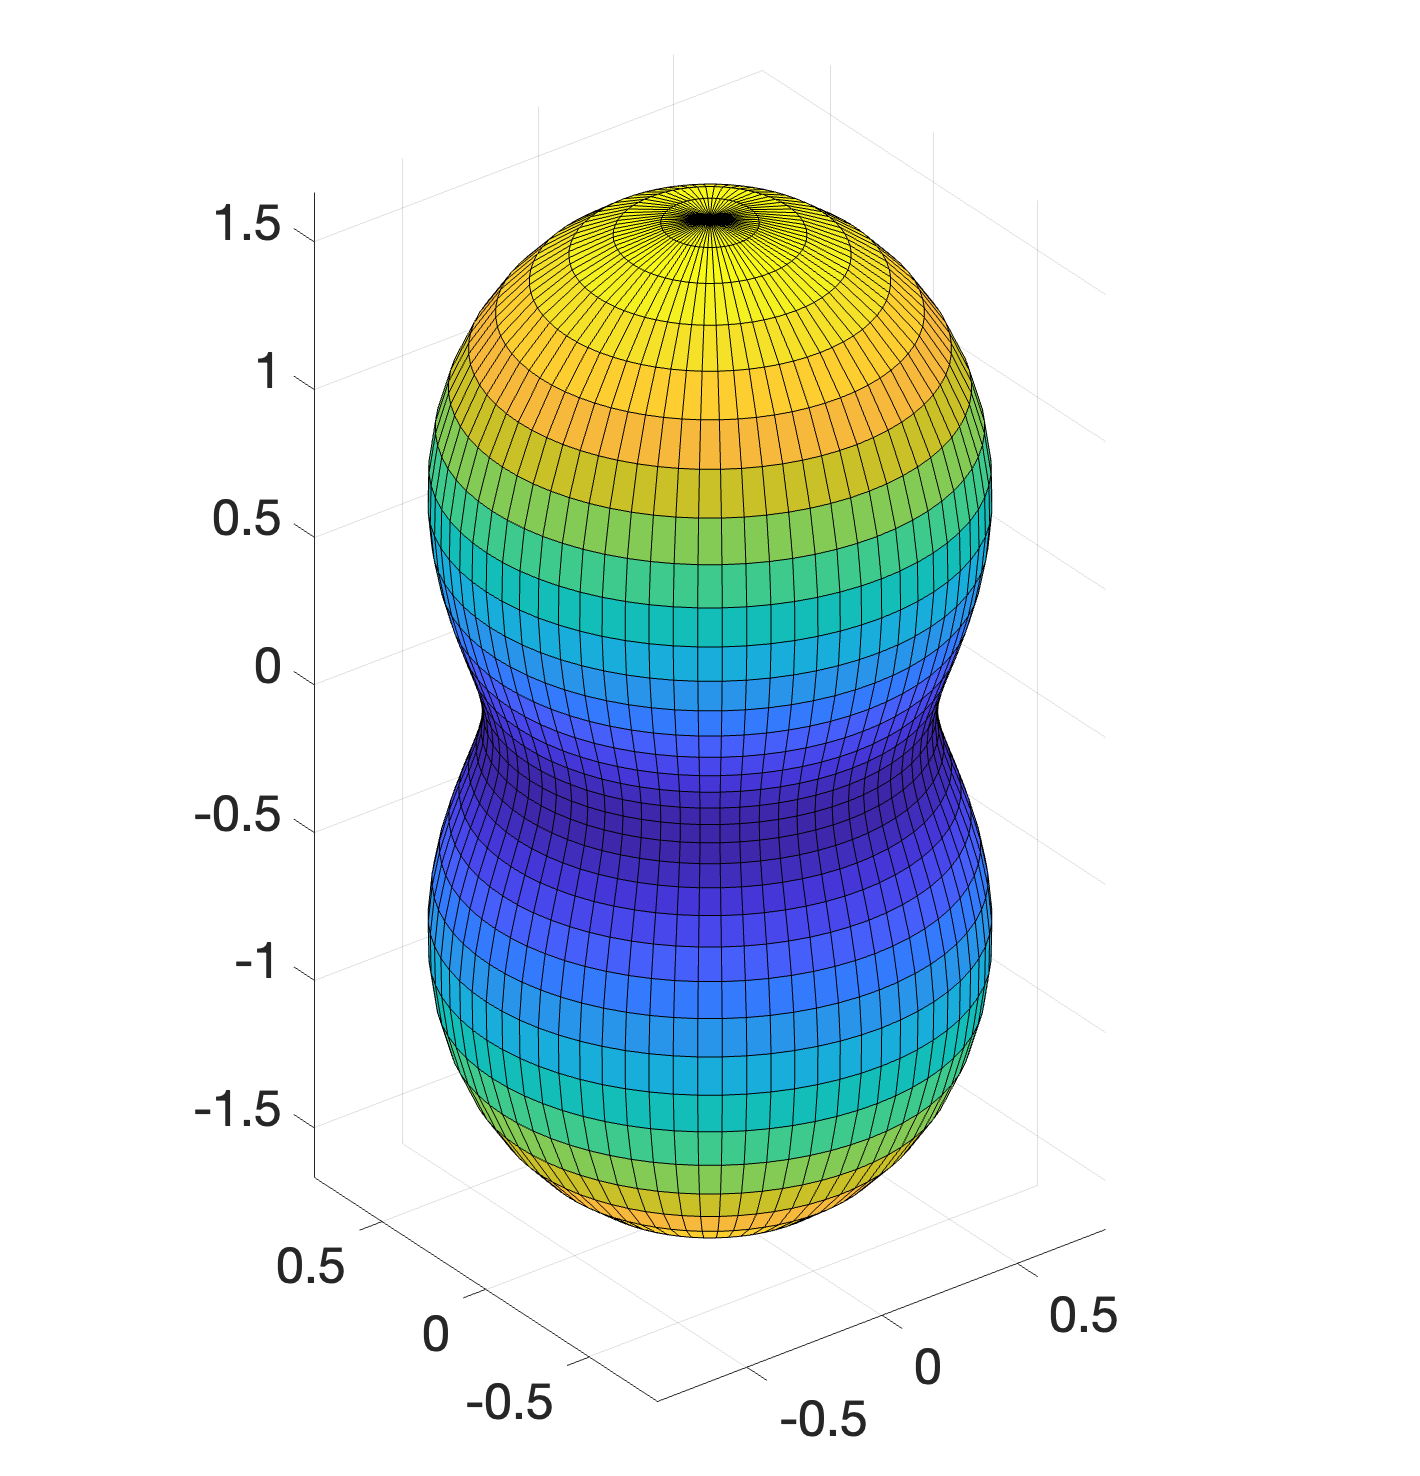


% plot the thermal expansion tensor surface (hyperboloid)

figure (2)
surf(k_cal.directionalMagnitude)

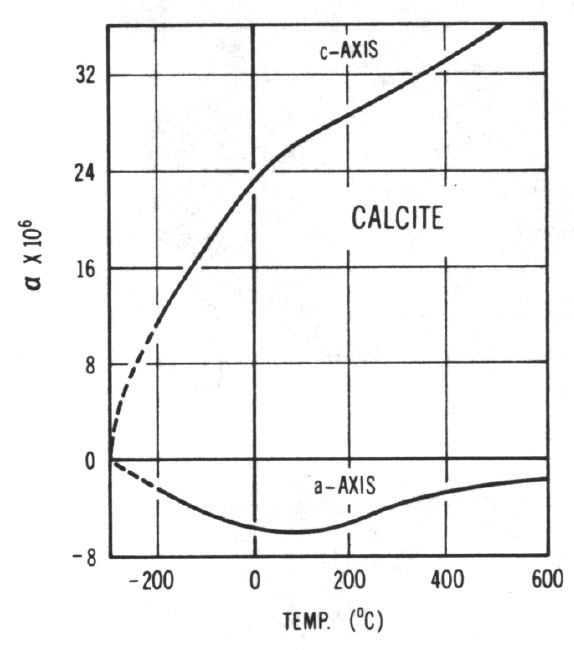

## The effect of symmetry on 2nd rank tensors

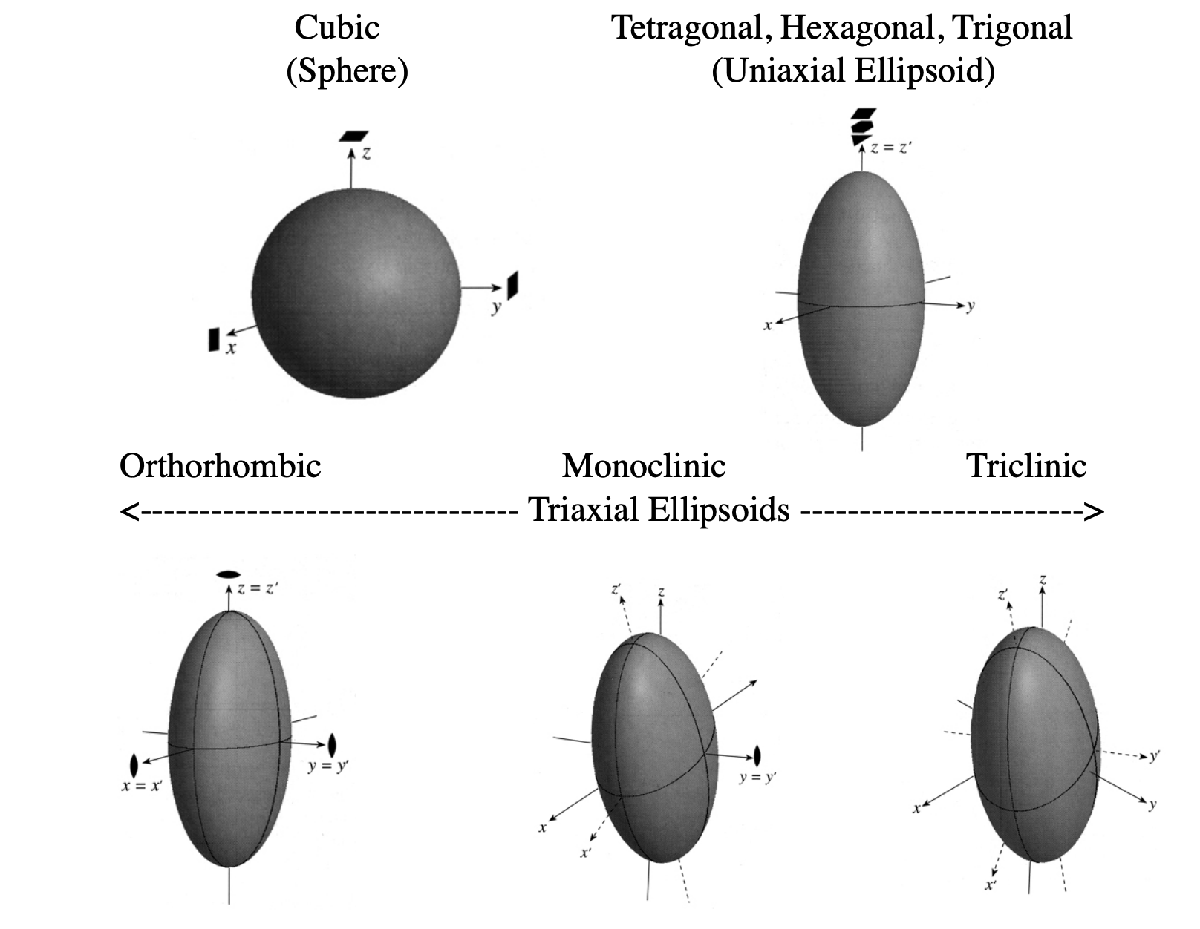

## Piezoelectricity

- Eletrical charge that accumulates in certain solids in response to applied stress

- Some geological materials, some ceramics and even biological matter (e.g. bones, some proteins) have piezoeletric properties

- Piezoeletricitiy is reversible - removing the stress will remove the induced eletrical field

- The semi-conducting elements tellurium (Te) and selenium (Se), along with the mineral pyrolusite (MnO2), have the greatest piezoelectric effect of naturally occurring compounds.

## Direct effect - applying stress to generate electric current

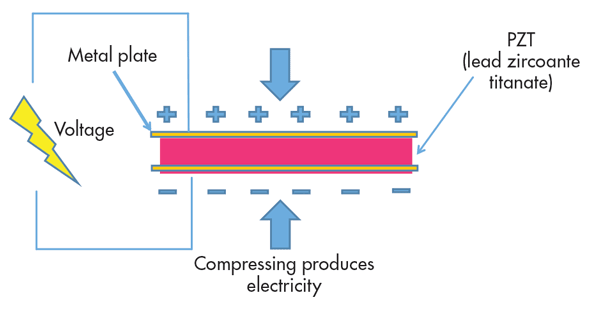

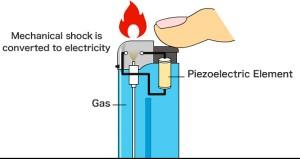

Figure source: https://www.autodesk.com/products/eagle/blog/piezoelectricity/

## Piezoeletricity in quartz

 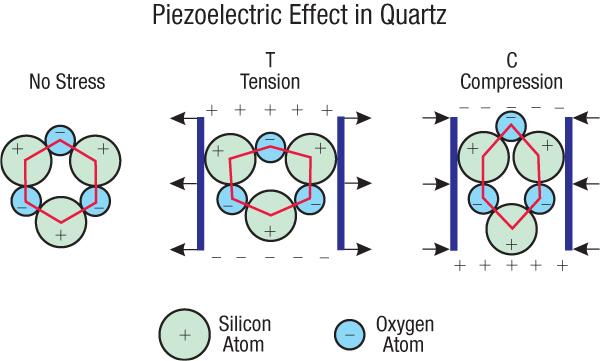

Figure source: [https://www.autodesk.com/products/eagle/blog/piezoelectricity/](https://www.autodesk.com/products/eagle/blog/piezoelectricity/)

## Some basics on piezoeletricity 3rd-rank tensor

- The direct effect can be written as the relationship between the 2nd rank stress tensor  rank electric polarization vector Pi, linked by the piezoelectric tensor dijk as follows

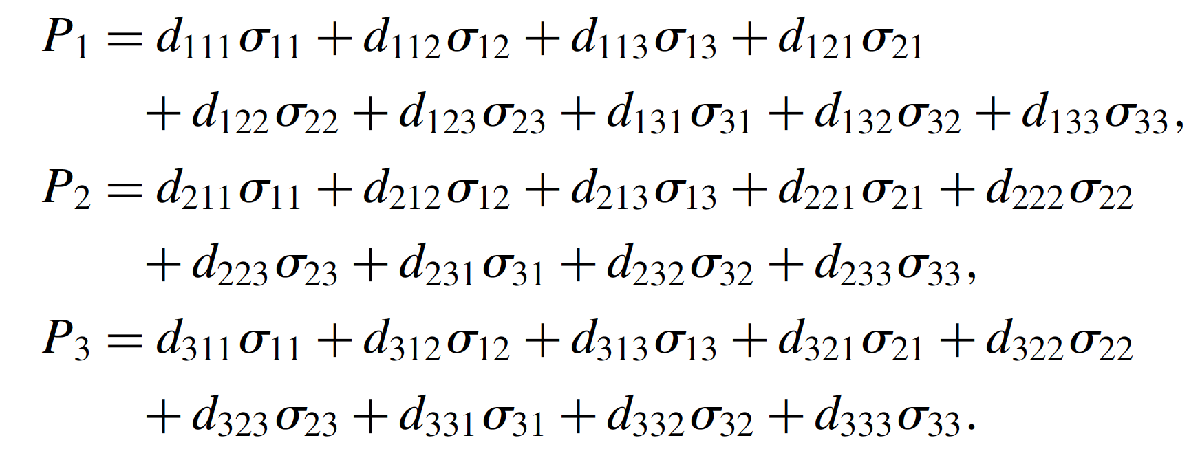

- This can be written in a more compact tensor notation:

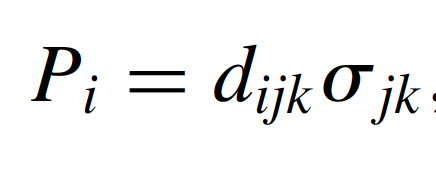

- In this equation **P**i is the electric polarization, **d**ijk is the piezoeletric tensor and  **sigma jk **is the stress tensor

- The piezoelectric tensor will always have three indices and Voigt matrix notation two indices. The direct and converse effects can also be written in Voigt matrix notation as

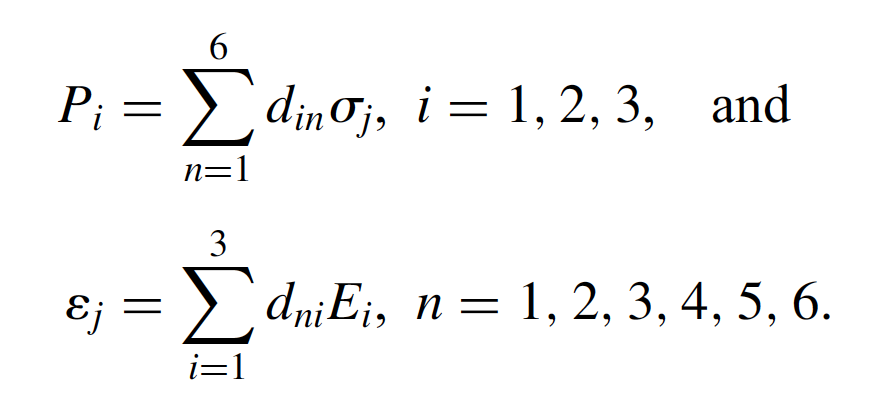

## The piezoelectric tensor

- 1st rank electric polarization (Pi) and electric field (Ek) vectors have the index i=1,2 or 3

- 2nd rank stress $\sigma \textrm{ij}$ and elastic strain $\varepsilon \textrm{jk}$also have indices j=1,2,3 and k=1,2,3, sp the piezoelectric tensor *d*ijk has 3 x 3 x 3 (=27) coefficients

- The stress and strain 2nd rank tensors  are symmetric for linear elasticity, resulting in interchangeability of jk and kj indices of piezoelectric tensor dijk

- That reduces the number of independent components to 18, im the case of triclinic crystals

- This number is considerably reduced in higher crystalline symmetries. In the case of monoclinic crystals that have a 2-fold rotation of 180° around [b]or-[c]-axis, the number of independent components is reduced to 8, and can be 1 in the case of hexagonal -62 and cubic -43m

## Symmetry properties related to piezoelectricity

- Crystals that belong to centrosymmetric point groups (i.e. the 11 Laue classes) are piezoelectrically inactive

- All crystals belonging to the 21 noncentrosymmetric point groups are piezoelectrically active, with the exception of cubic 432

- In the 432 point group, the presence of four-fold axes parallel to [100], [010] and [001] makes all directions perpendicular to these axes non-polar

- Because of that, all the tensor oefficients that are non-zero in two other piezoeletric cubic point groups 23 and -43m (d14=d25=d36), are zero in 432

- That results in 20 non-centrosymmetric point groups for piezoelectric active crystals, where 10 enantiomorphic space group pairs do not have improper rotations (i.e. no mirror planes).

- Such crystals occur in right-handed and left-handed forms (e.g. a-quartz) and are distributed in 6 point groups (4, 422, 3, 32, 6 and 622)

## Loading quartz piezoelectricity in MTEX

% Define quartz tensor reference frame

cs_tensor_quartz = crystalSymmetry('32', [4.916 4.916 5.4054],...
    'X||a*', 'Z||c', 'mineral', 'Quartz');

% Load the tensor (this one can be loaded automatically from MTEX)

fname = fullfile(mtexDataPath,'tensor', 'Single_RH_quartz_poly.P');

P = tensor.load(fname,cs_tensor_quartz,'propertyname',...
    'piecoelectricity','unit','C/N','DoubleConvention') 

 
P = tensor (Quartz)
  propertyname    : piecoelectricity
  unit            : C/N             
  rank            : 3 (3 x 3 x 3)   
  doubleConvention: true            
 
  tensor in compact matrix form:
     0     0     0 -0.67     0   4.6
   2.3  -2.3     0     0  0.67     0
     0     0     0     0     0     0


## Making some colorful plots

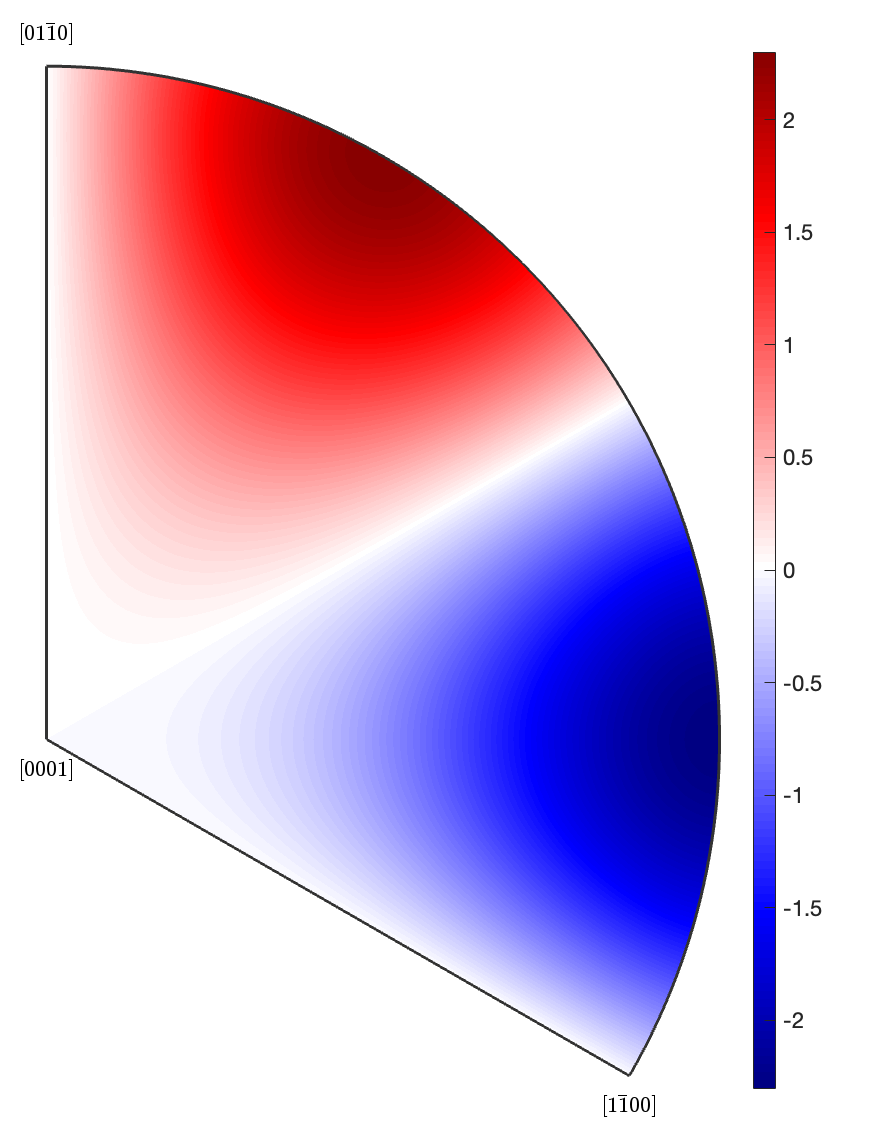

% Let's change the colorcode for the plots

setMTEXpref('defaultColorMap',blue2redColorMap);

% Now let's plot

plot(P)
mtexColorbar

This plot shows thew magnitude polarization variation, from red (strongest) to blue (weakest). As a standard, we use the unique region implied by crystal symmetry, that in the case of quartz (trigonal) is represented by a 120° sector of the full pole figure

One naturally can also plot the complete crystal behavior

% Plot quartz piezoelectricity (full circle)

plot(P,'complete','smooth','upper')
h = Miller({0,0,0,1},{1,1,-2,0},{2,-1,-1,0},{1,0,-1,0},{1,0,-1,1},...
    {0,1,-1,1},{1,0,-1,2},{0,1,-1,2},cs_tensor_quartz);
h_s=symmetrise(h)

 
h_s = Miller (Quartz)
 size: 6 x 8
 
  show Miller
 


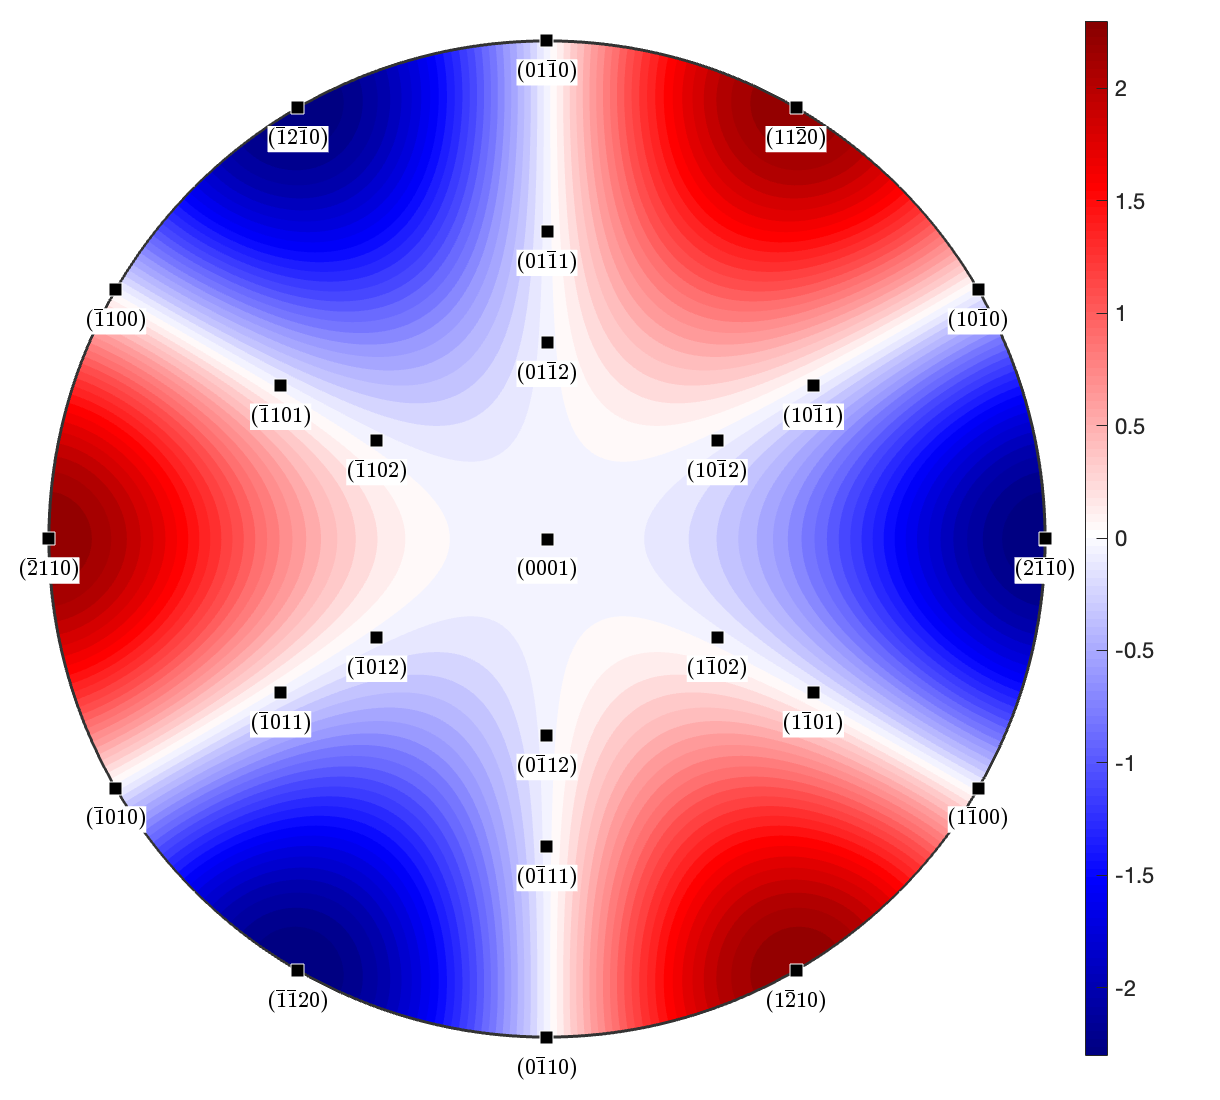

hold on
annotate(h_s,'labeled','backgroundColor','w','grid','upper','doNotDraw')
hold off
drawNow(gcm,'figSize','large')
mtexColorbar

As in the other examples, one can plot single crystal piezoelectricity as a surface

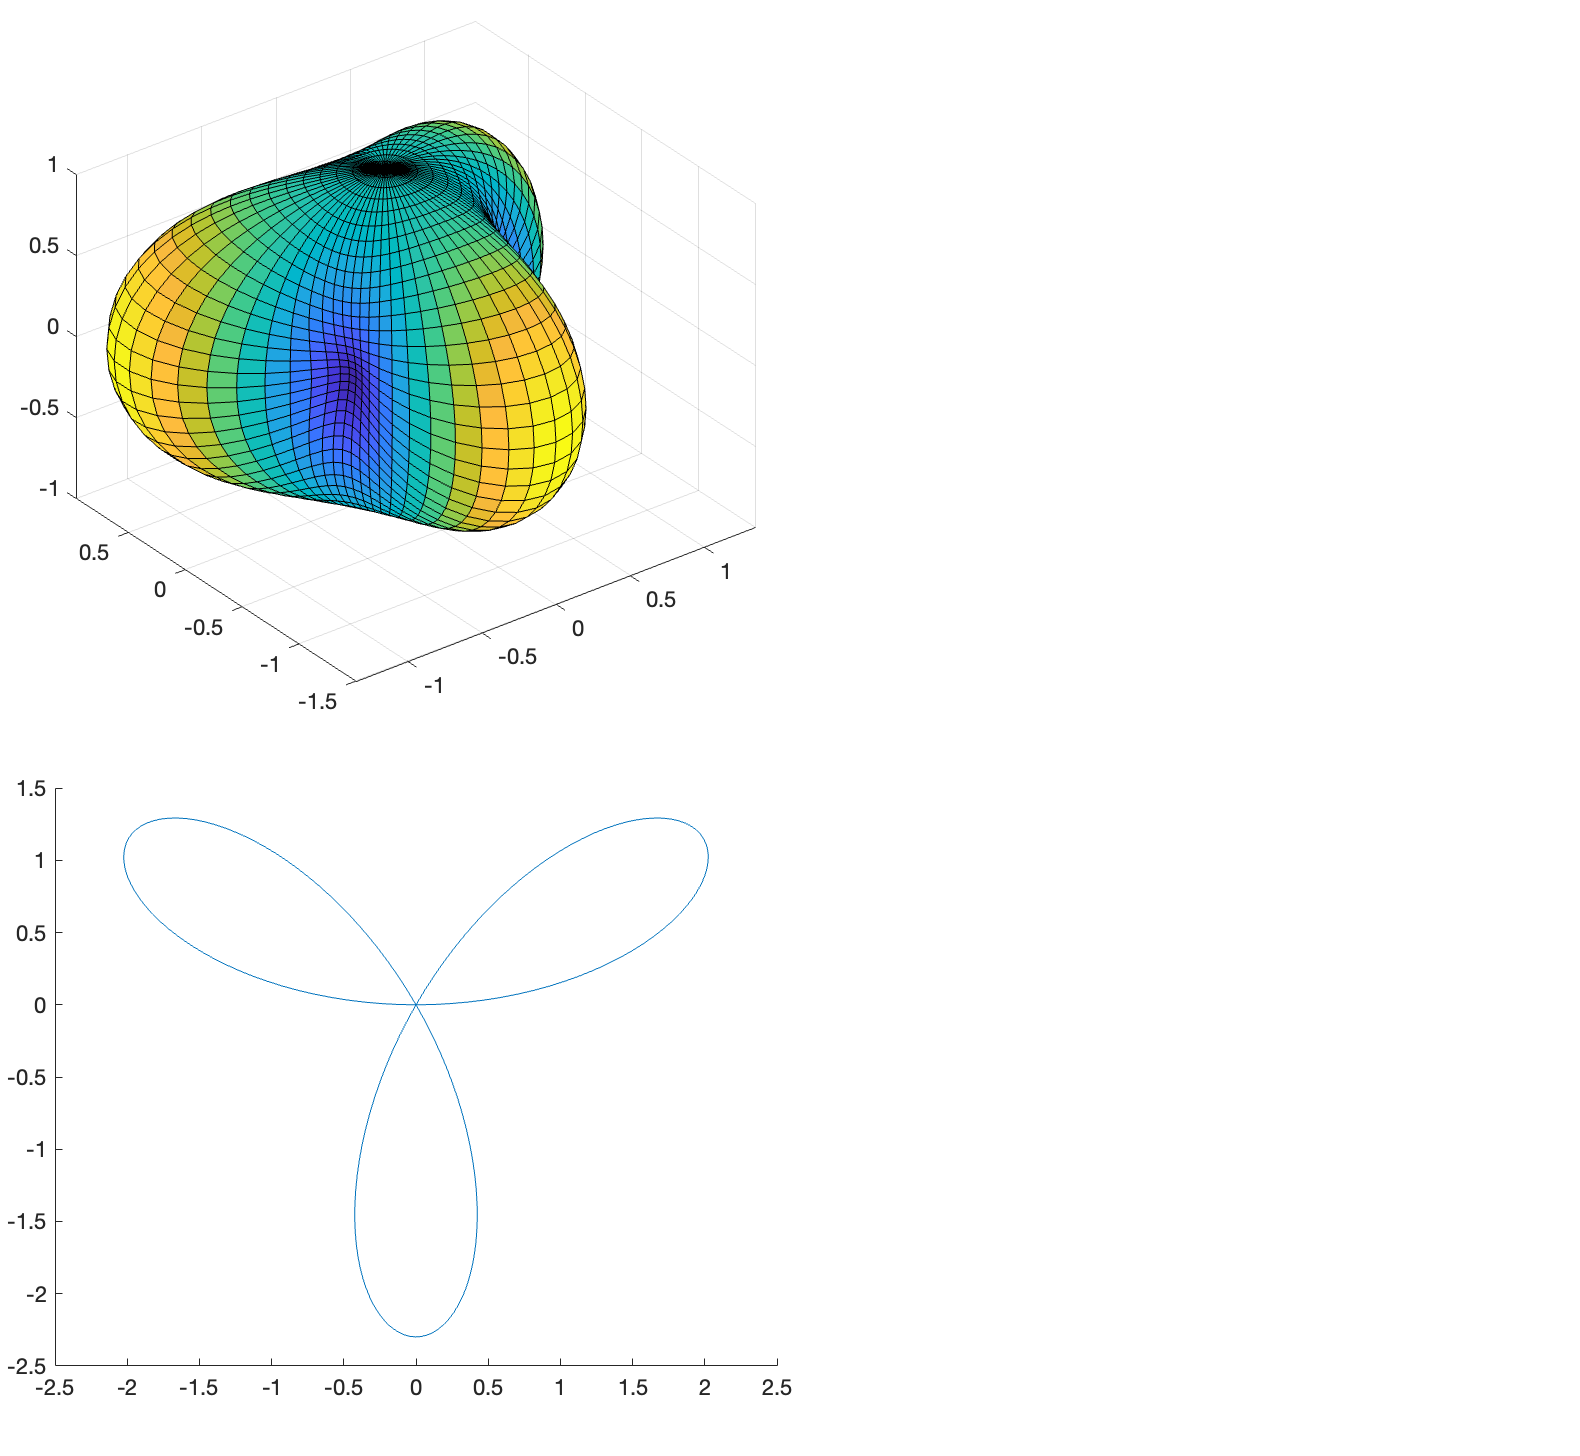

% Plot quartz piezoelectricity as a surface

surf(P.directionalMagnitude)

% Plot quartz piezoelectricity section along basal plane
nextAxis 
plotSection(P.directionalMagnitude,vector3d.Z)
axis on
drawNow(gcm)


## CPO-derived seismic properties - elasticity and 4th-rank tensor

## Why it is important?

•The calculation of the seismic properties from microstructural information (crystal orientation, volume fraction, grain shape etc.) is important for rocks because it gives insight into the role of microstructure in determining the bulk properties;

•Can be calculated for the conditions where the microstructures were developed via using the appropriate single crystal derivatives;

•Additional features not necessarily preserved in the recovered microstructure, such as the presence of fluids (e.g. magma) can be modeled;

•The effect of phase change on the seismic properties can also be modeled using these methods;

•Modeling is essential for understanding anisotropic properties as experimental measurements in the many directions necessary to fully characterize anisotropy is not currently feasible for the majority of the temperature and pressure conditions found in the deep Earth.

## What causes seismic anisotropy in rocks?

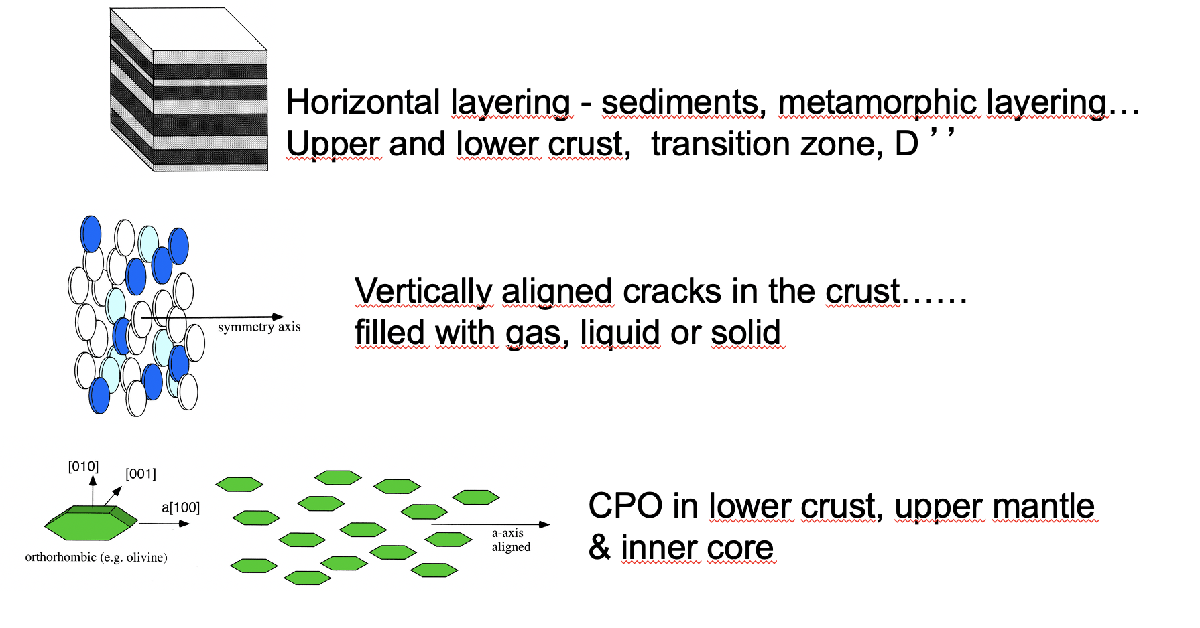

## Shear wave splitting

[https://en.wikipedia.org/wiki/Shear_wave_splitting#/media/File:Garnero_Splits.gif](https://en.wikipedia.org/wiki/Shear_wave_splitting#/media/File:Garnero_Splits.gif)

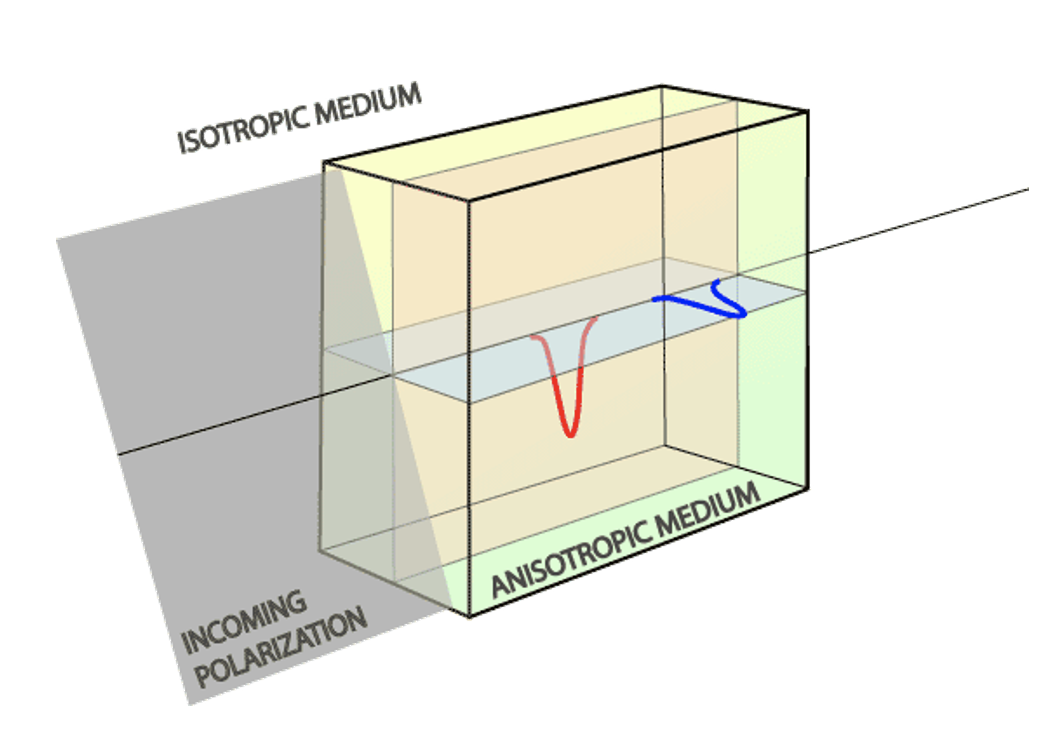

## Elasticity - a 4th-rank tensor

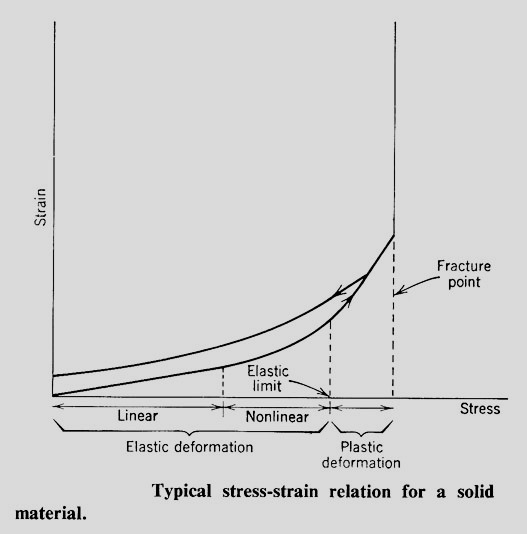

### Hooke’s Law

**σ** = *c* **ε** and **ε** = *s ***σ**

where 

*c* = stiffness coefficients (dimensions of stress)

*s *= compliance coefficients (dimensions of 1/stress)

**σ **= stress tensor (second order symmetric tensor)

**ε** = deformation tensor (second order symmetric tensor)

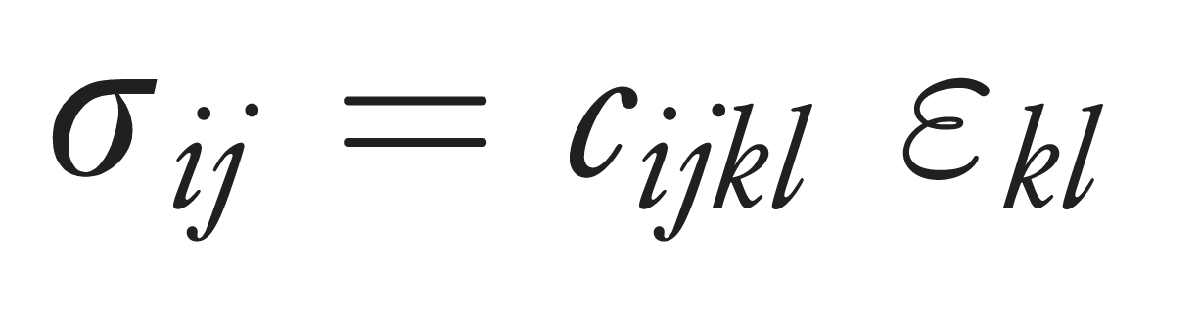

- i,j,k,l can have the values 1,2 or 3 so 3 x 3 x 3 x 3 = 34 = 81 coefficients

- 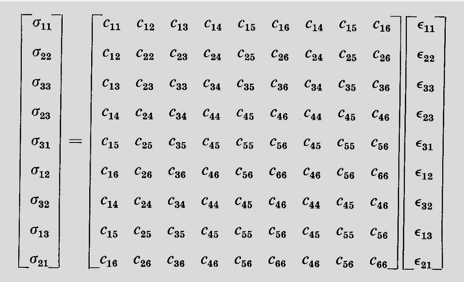

- The **stress tensor is symmetric** -  stresses acting on opposite faces are equal and opposite - no stress couples to produce a net rotation of the elastic material;

- The **infinitesimal strain tensor is also symmetric** - pure and simple shear quantities are so small that their squares and products can be neglected

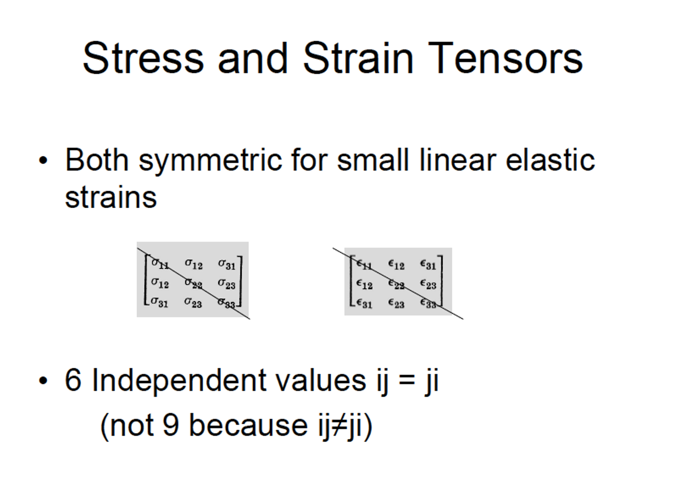

- because of that the stress and strain tensor have six Independent values and the first two (i, j) and second two (k, l) indices of the elastic tensor can be interchanged

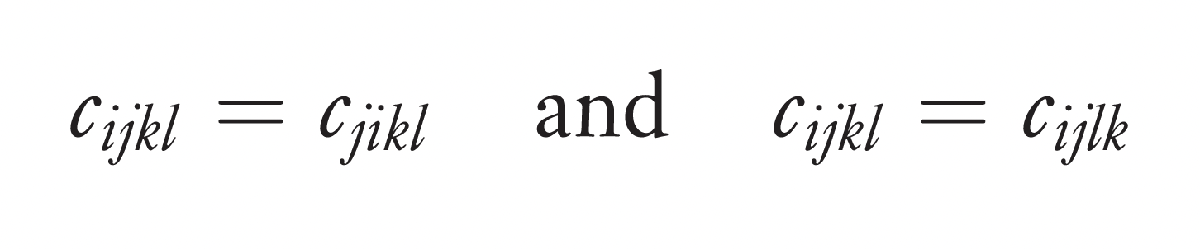

- The permutation of the indices caused by the symmetry of stress and strain tensors reduces the number of independent elastic coefficients to 36 because the two pairs of indices (i, j ) and(k, l ) can only have six different values:

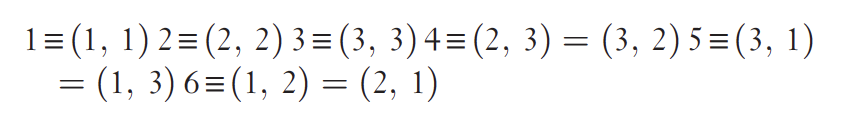

- In practice, elasticity tensors are written in the Voigt notation with 36 elements (6 x 6 matrix) with Voigt indices ***m*** and ***n (Cmn) ***with values from 1 to 6

- The relation between the tensor notation with indices ijkl and the Voigt notation is given by

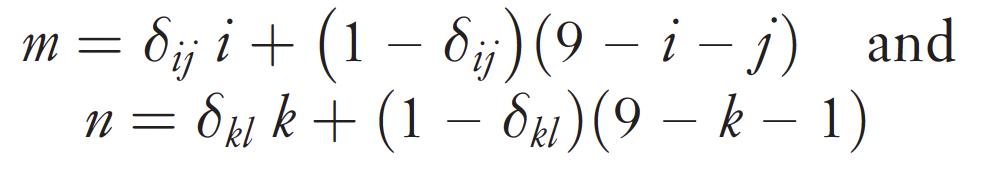

- The Kronecker delta = 1 when i=j and 0 when i≠j;

- There are also a number of considerations related to the first and second laws of thermodynamics for stress-strain variables 

- variation of internal energy per volume of deformed anisotropic elastic body as a function of entropy and elastic strain as function of T

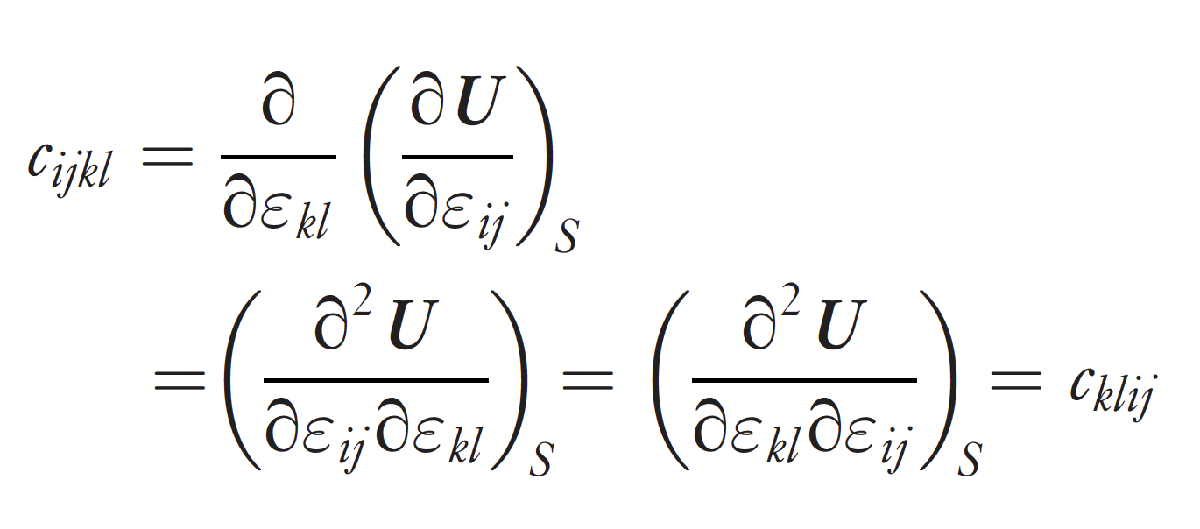

- from the thermodynamics arguments, it follows that we can interchange the first pair of indices **(ij)**  with the second **(kl)**

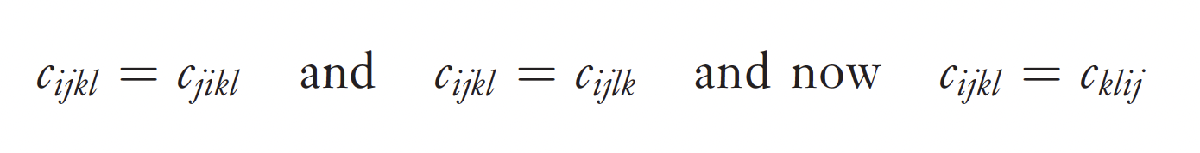 

- This additional symmetry ***Cijkl*** = ***Cklij ***permutation reduces the number of independent elastic constants to 21

#### Take home message - Life is not meant to be easy with elasticity :-D

## Crystal symmetry plays a important role, 

## In the case of less symmetric materials (triclinic) - there will be...

## 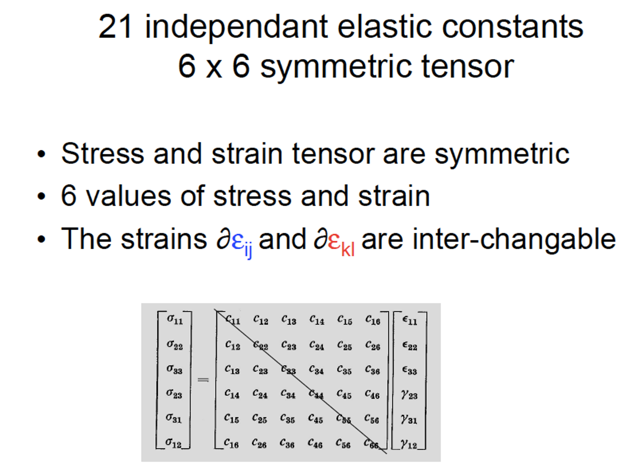

## Tensor in a cubic material

- There are a maximum of 21 elastic constants for a crystalline body, but for cubic crystals the elastic constants, cij may be reduced to just three independent elastic constants:

- c11= c22 = c33 ⇒ modulus for axial compression, i.e., a stress σ11results in a strain ε11along an axis;

- c44 = c55 = c66 ⇒ shear modulus, i.e., a shear stress σ23results in a shear strain ε23 across a face;

- c12 = c13 = c23 ⇒ modulus for dilation on compression, i.e., an axial stress σ11results in a strain ε22 along a perpendicular axis.

- All other cij = 0.

## Tensors and the crystalline symmetry

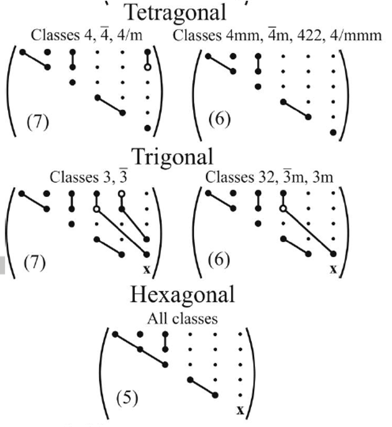

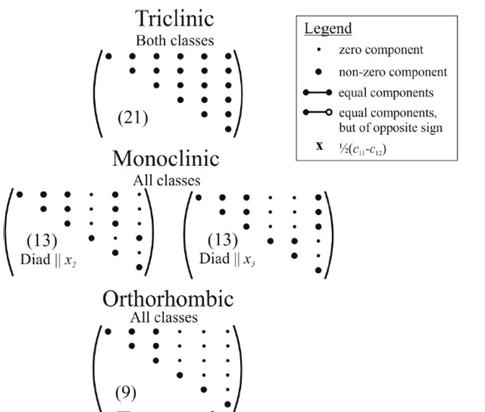

from Almqvist & Mainprice 2017 

## What can you do with elastic constants?

- Volume compressibility

- Linear compressibility

- Young's modulus

- Shear Modulus

- Poisson's ratio

- Christoffel tensor - seismic velocities

- etc...

## Let's upload the olivine single crystal elastic tensor

#### First we define the single crystal tensor reference frame (olivine)

cs_tensor_olivine = crystalSymmetry('222', [4.762 10.225 5.994],...
    'mineral', 'olivine', 'color', 'light red');

#### Then we define the density of the material (g/cm3)

rho_olivine = 3.3550;

#### And the coefficients Cij for olivine in Voigt notation (Abramson et al., 1997 - JGR)

Cij = [[320.5  68.15  71.6     0     0     0];...
       [ 68.15  196.5  76.8     0     0     0];...
       [  71.6   76.8 233.5     0     0     0];...
       [   0      0      0     64     0     0];...
       [   0      0      0      0    77     0];...
       [   0      0      0      0     0  78.7]];

#### To define the stiffness tensor, you will use the command stiffnessTensor

C_olivine = stiffnessTensor(Cij,cs_tensor_olivine,'density',...
    rho_olivine);

#### Now you can plot a certain number of properties derived from the stiffness tensor. 

#### For instance, Young's modulus

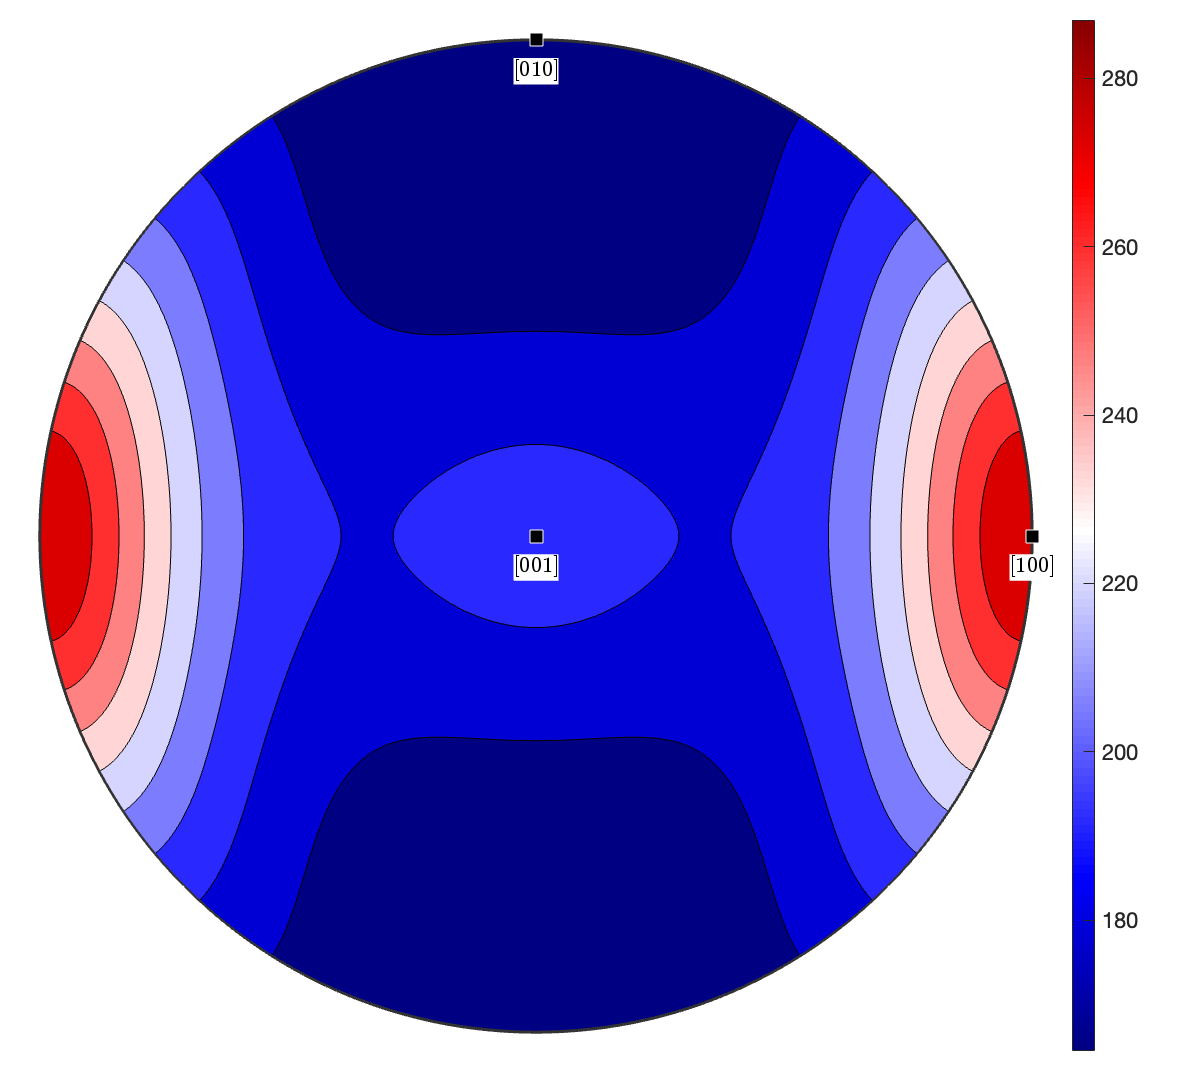

 setMTEXpref('defaultColorMap',blue2redColorMap);
 figure(1)
 plot(C_olivine.YoungsModulus,'complete','upper','contourf');
 mtexColorbar
 h = Miller({1,0,0},{0,1,0},{0,0,1},cs_tensor_olivine,'uvw');
 hold on
 annotate(h,'labeled','backgroundColor','w','grid','upper',...
     'doNotDraw')
 hold off
 saveFigure ('olivine single crystal youngs modulus.png')

#### Or the linear compressibility

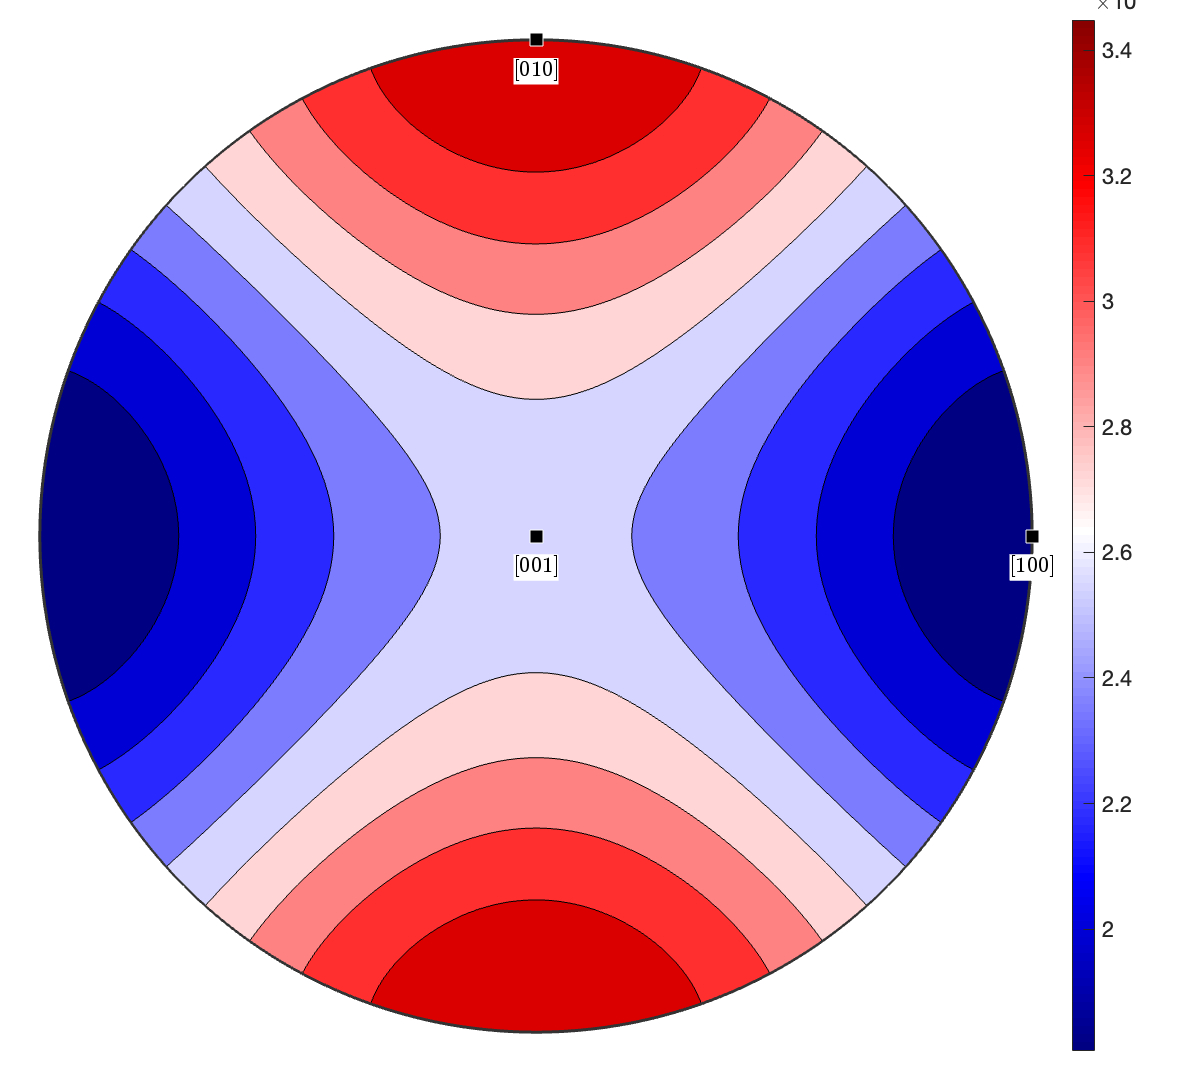

figure(2)
 plot(C_olivine.linearCompressibility,'complete','upper','contourf');
 mtexColorbar
 h = Miller({1,0,0},{0,1,0},{0,0,1},cs_tensor_olivine,'uvw');
 hold on
 annotate(h,'labeled','backgroundColor','w','grid','upper',...
     'doNotDraw')
 hold off
 saveFigure ('olivine single crystal linear compressibility.png')

#### The single crystal seismic velocities are computed with command seismicVelocities

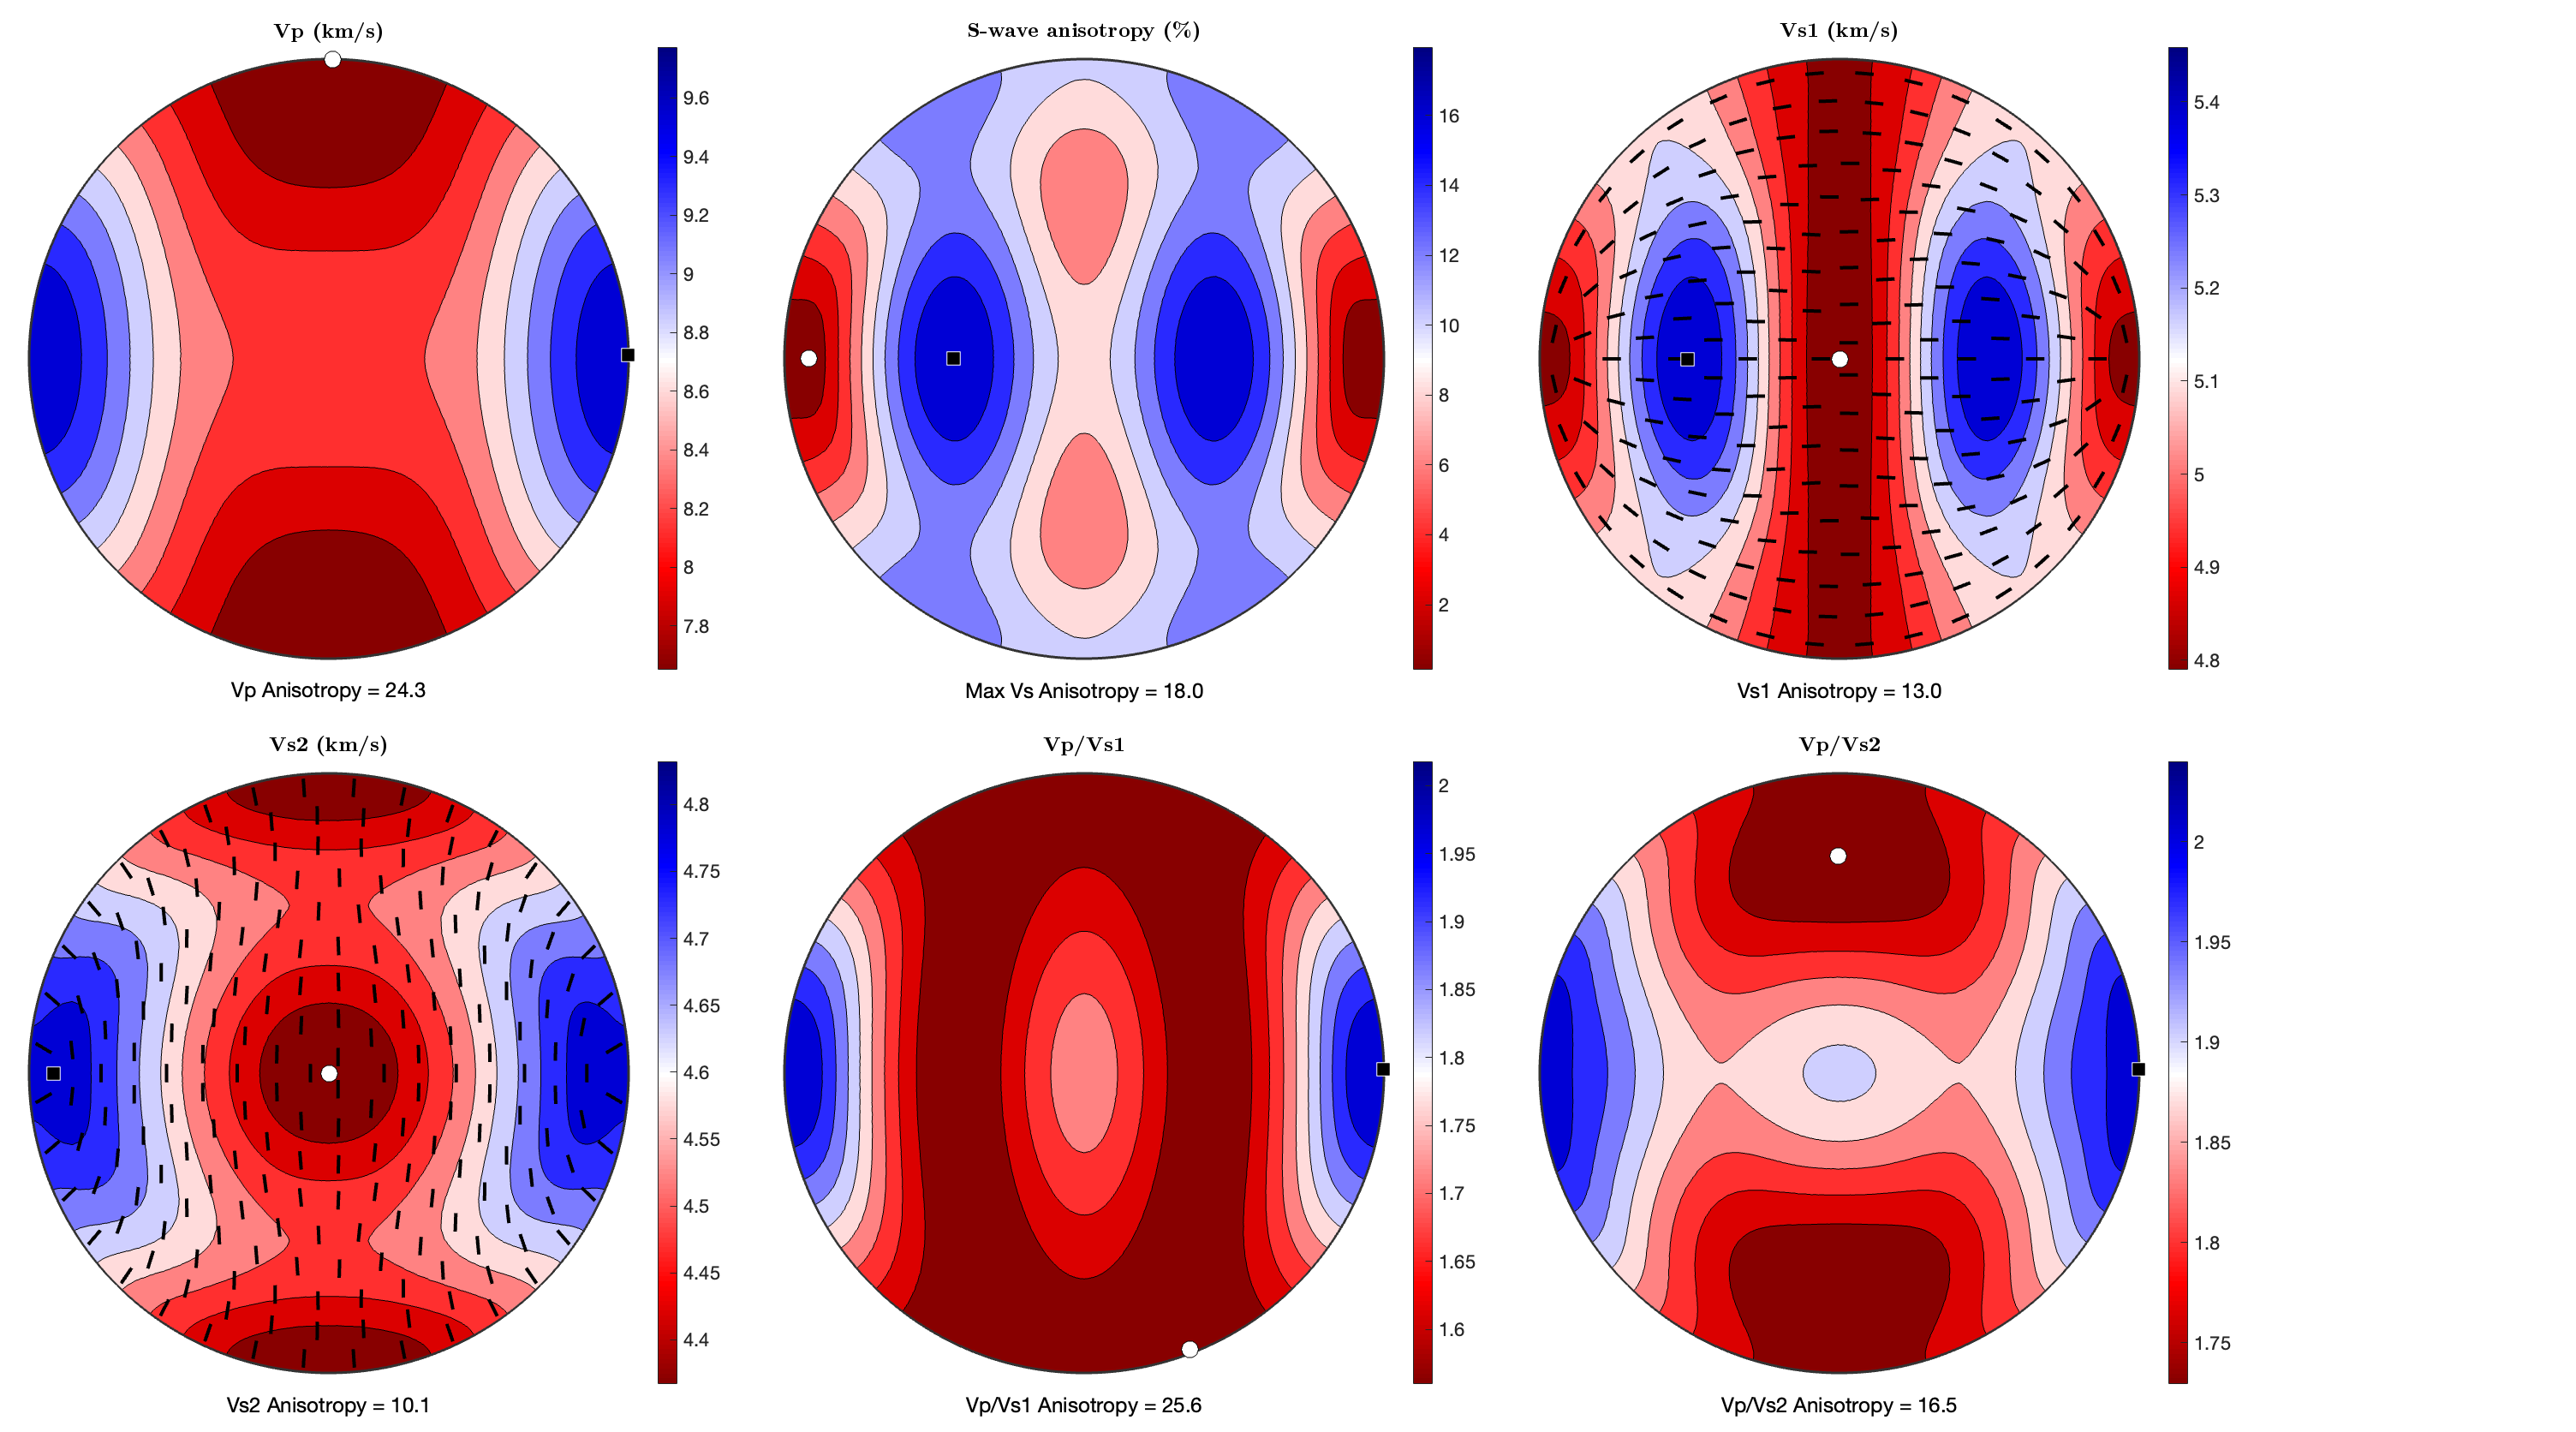

plotSeismicVelocities(C_olivine)

## Calculating CPO-derived seismic properties

### First, we have to calculate an ODF

- In texture analysis, the orientation of a crystal is defined historically by the letter g, where=(φ1,ϕ, φ2) - an Euler angle triplet;

- The ODF f(g) is the volume fraction of orientations within an orientation range between **g **and **g**+d**g**, in a space containing all possible orientations given by

- Region of integration in orientation space – symmetrically controlled;

- The ODF is normalized and ODF densities are expressed in multiples of the uniform density (m.u.d.). The normalization for the ODF is given by

- For a uniform distribution the ODF density is 1 for all orientations in the ODF, defined by f(**g**)uniform=1

- The strength of preferred orientation of an ODF may be expressed by the ODF texture index

## Cartesian Reference Frame

- Cartesian frame defined by orthogonal crystallographic directions used to report single crystal elastic properties may not be the same as those used for Euler angle reference frame (texture analyses);

- Crystallographic reference frame of tensor needs to be rotated to bring it into coincidence with Euler angle frame,

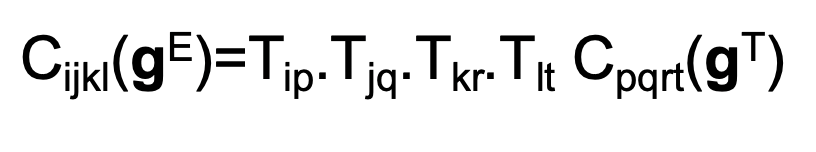

- Here Cijkl(**g**E) is the elastic property in the Euler reference and Cpqrt(**g**T) is the elastic property in the original tensor reference frame, BOTH  frames are in crystal  co-ordinates. 

- To calculate the seismic properties of a polycrystal, one must evaluate the elastic properties of the aggregate;

- In an aggregate with CPO, the anisotropy of single crystal elastic properties need to be considered;

- For each orientation **g,** the single crystal properties have to be rotated into the specimen co-ordinate

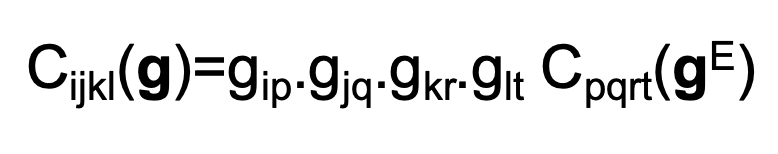

- Here, Cijkl(**g**) is the elastic property in sample co-ordinates, gij is the crystal orientation in sample co-ordinates and Cpqrt(**g**E) is the elastic property in crystal co-ordinates of the Euler frame (E).

## Elastic constant averaging schemes - Voigt and Reuss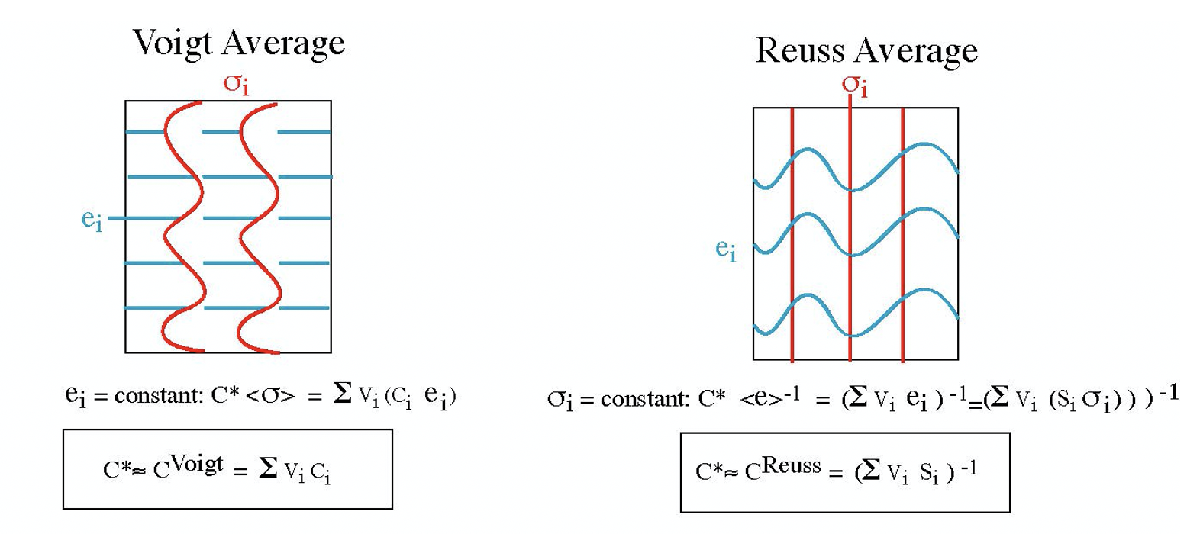

### Advantages

- easy to calculate

- widely separated bounds for highly anisotropic phases

### Disadvantages

- cannot introduce microstructural effect (e.g. grain shape)

- very poor bounds for mixtures of materials with very different stiffness (e.g. solids + liquids + voids)

- In this cases, better to use differential effective media or self-consistent approaches (to be incorporated on MTEX)

## Elastic properties of an aggregate

- The elastic properties of the polycrystal may be calculated by integration over all possible orientations of the ODF.

where <Cijkl>m is the elastic properties of the aggregate of mineral m.

- Alternatively it may be determined by simple summation of individual orientation measurements (e.g. U-stage or EBSD), 

- in the equation above, V(**g**) is the volume fraction of the grain in orientation **g**

## **Christoffel equation & Tensor**

- The final step is the calculation of the three seismic phase velocities by the solution of the Christoffel equation,

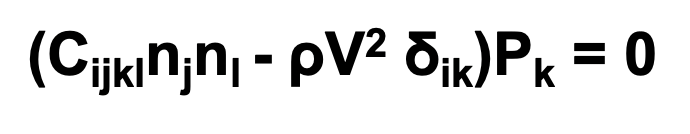

- Here, V are the phase velocities, ρ is the density of the rock, nj is the propagation unit vector (propagation direction), Pk  is the polarization unit vectors (polarization direction), and Cijkl is the aggregate elastic constant;

- The polatization unit vectors Pk are obtained as eigenvectors and eigenvalues of the roots of the equation

## Vp anisotropy of some minerals

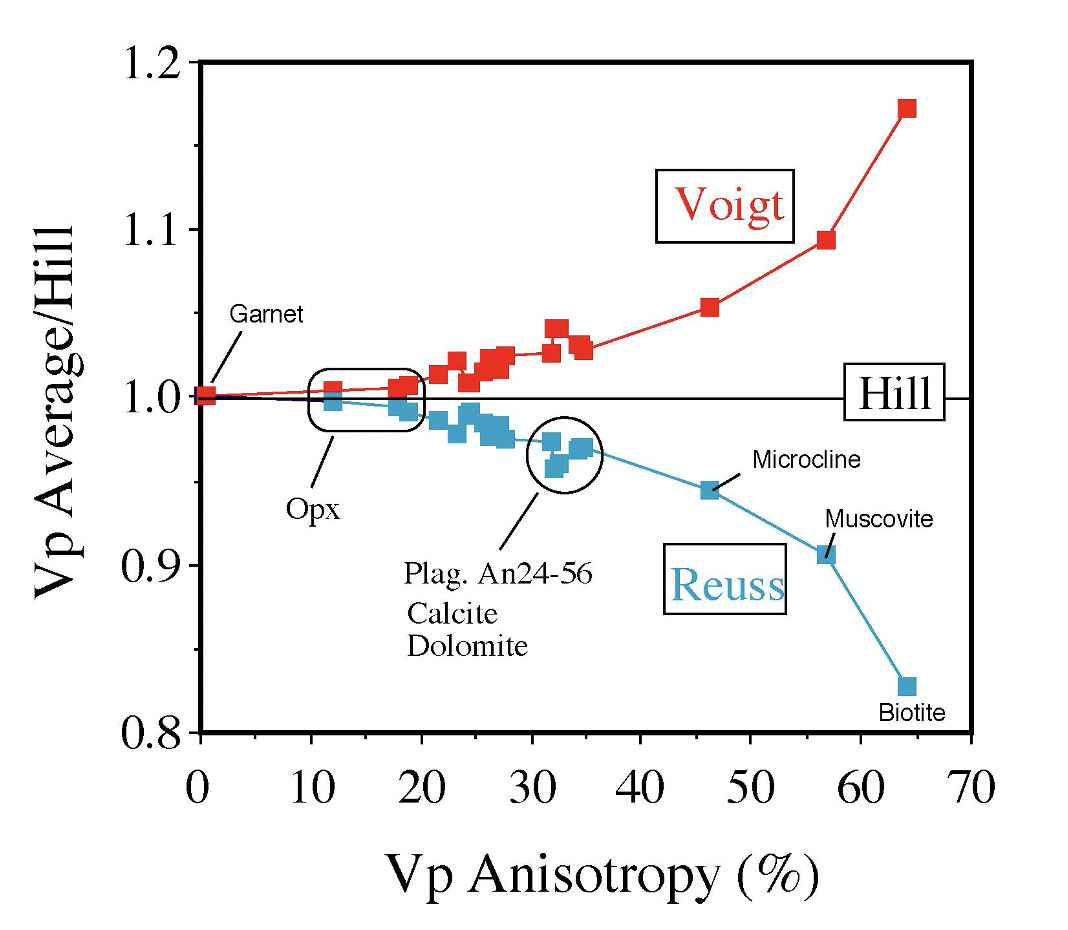

## Vp anisotropy of some mantle minerals

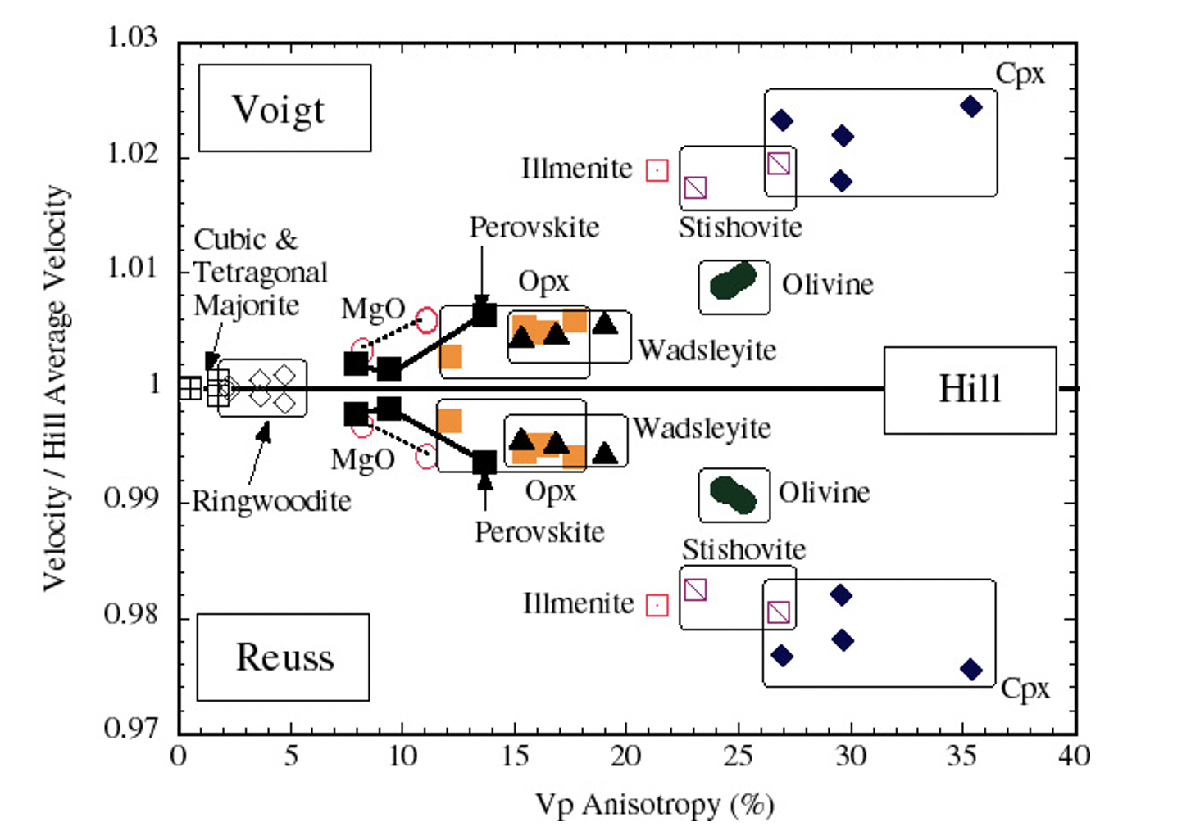

## Calculating CPO-derived seismic properties

### Let's import some data

mtexdata forsterite

 
ebsd = EBSD
 
 Phase  Orientations     Mineral         Color  Symmetry  Crystal reference frame
     0   58485 (24%)  notIndexed                                                 
     1  152345 (62%)  Forsterite  LightSkyBlue       mmm                         
     2   26058 (11%)   Enstatite  DarkSeaGreen       mmm                         
     3   9064 (3.7%)    Diopside     Goldenrod     12/m1       X||a*, Y||b*, Z||c
 
 Properties: bands, bc, bs, error, mad
 Scan unit : um
 


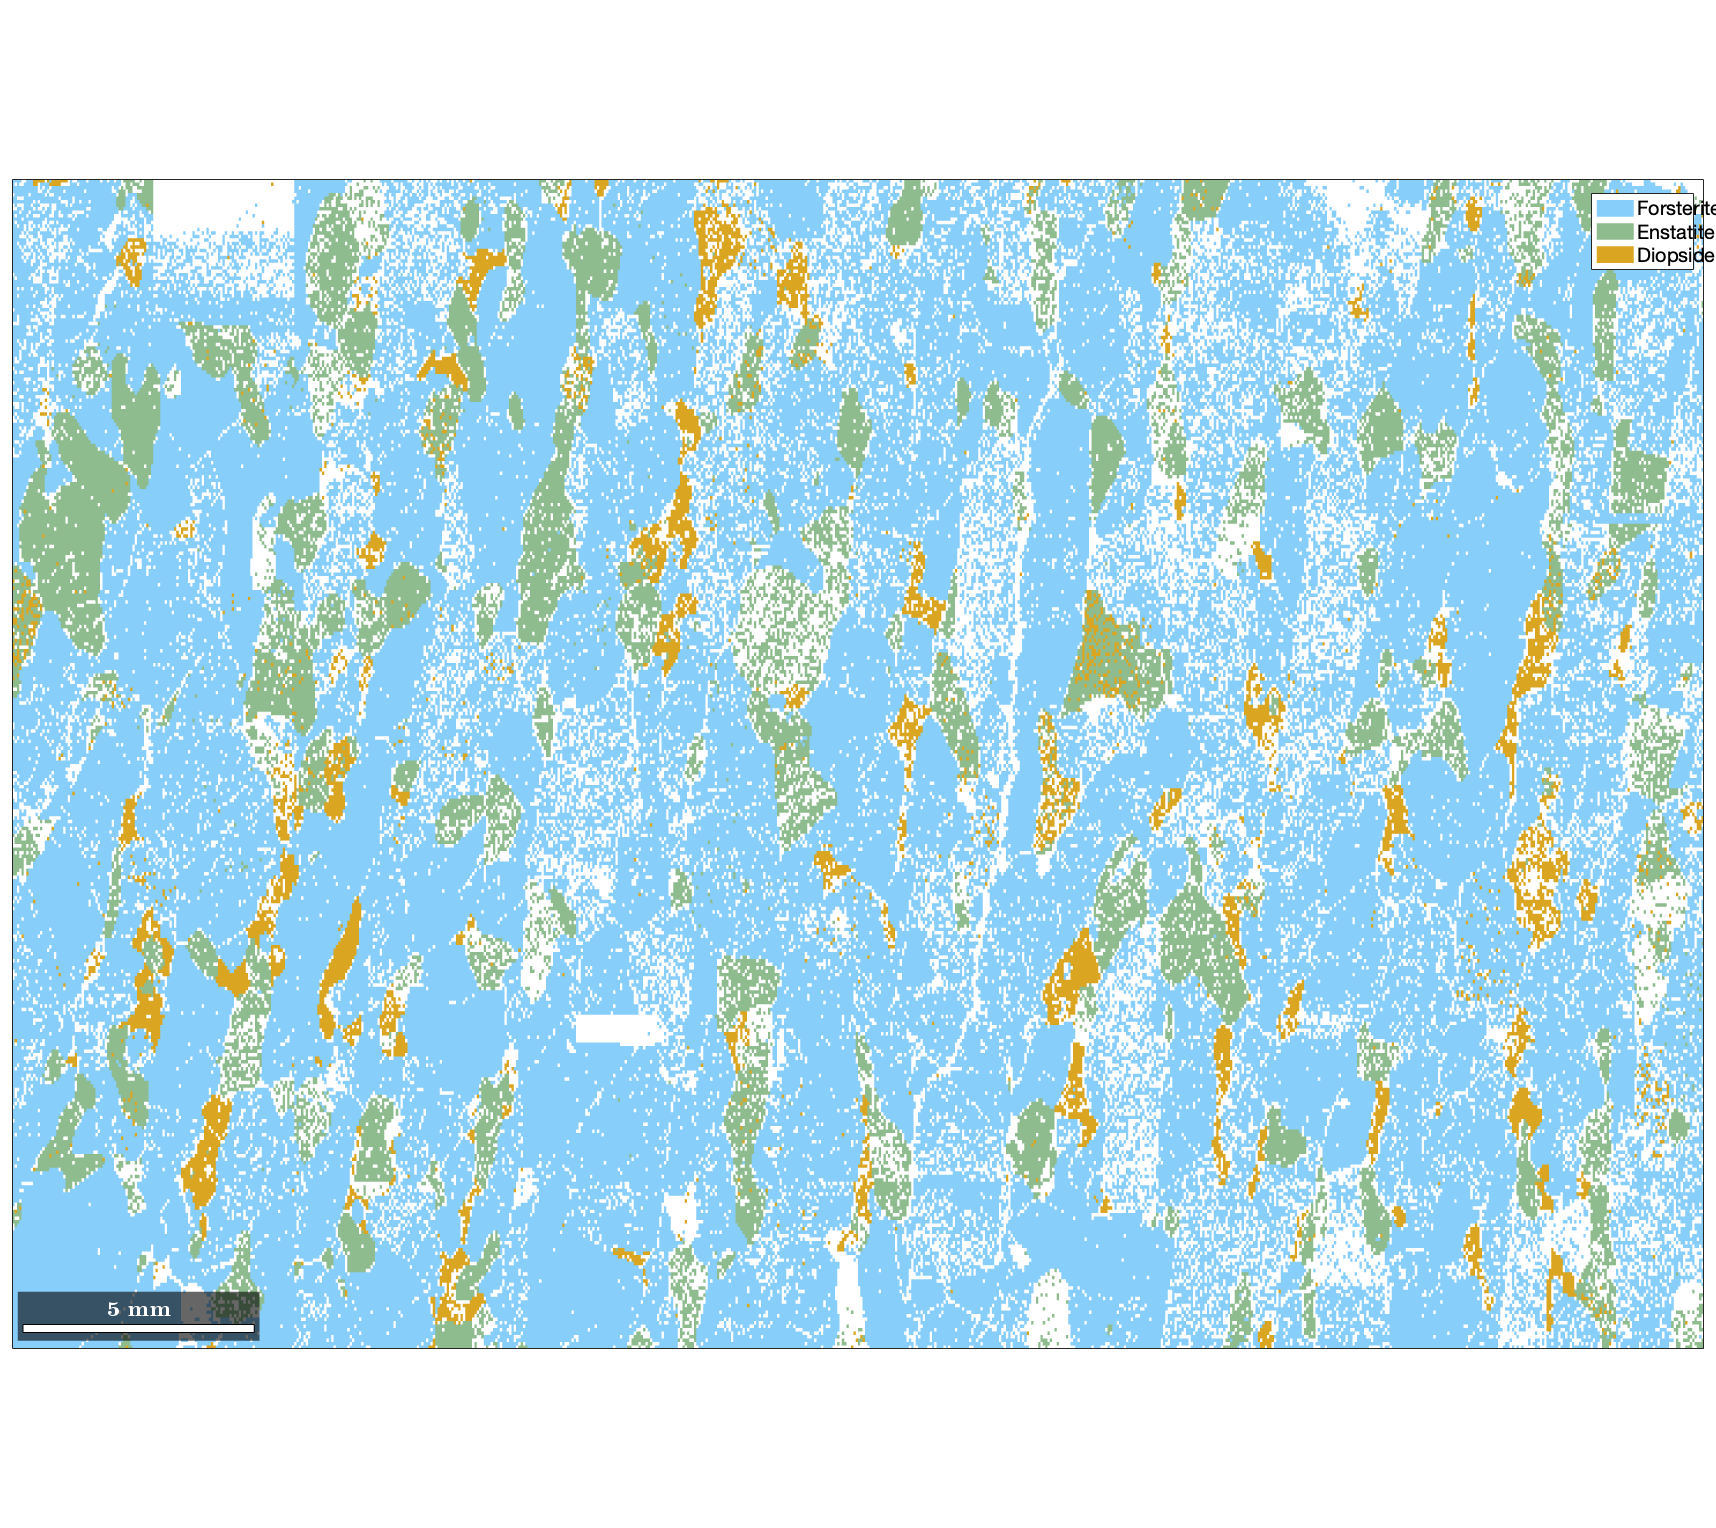

plot (ebsd)

### We need now to rotate the data, to have the foliation here in the horizontal position

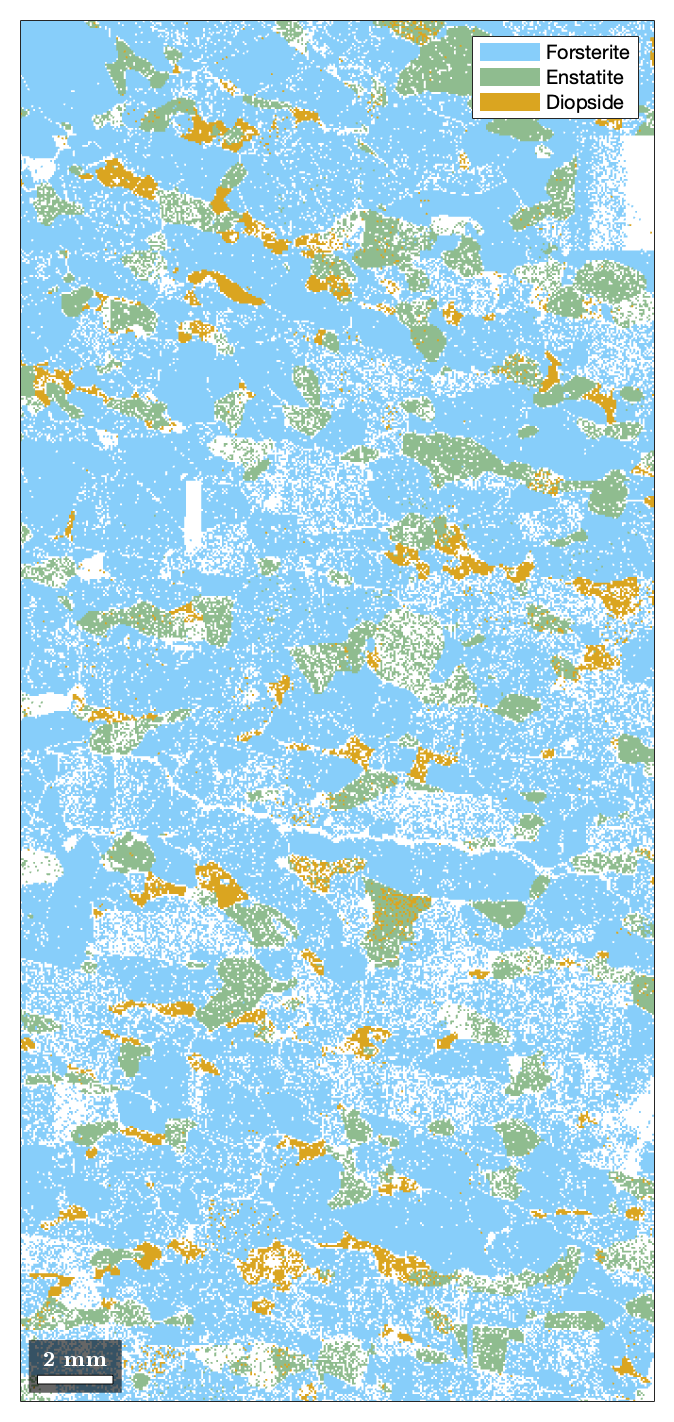

ebsd = rotate(ebsd,rotation('axis',-zvector,'angle',90*degree));
plot(ebsd)

### Now we import the single crystal elastic tensors we need

- The elastic stiffness tensor of Olivine was reported in Abramson et al., 1997 (Journal of Geophysical Research) with respect to the crystal reference frame

CS_Tensor_olivine = crystalSymmetry('222', [4.762 10.225 5.994],...
    'mineral', 'olivine', 'color', 'light red')

 
CS_Tensor_olivine = crystalSymmetry
 
  mineral : olivine   
  color   : light red 
  symmetry: 222       
  elements: 4         
  a, b, c : 4.8, 10, 6
 


- we also need the density of this phase

rho_olivine = 3.3550;

- and the coefficients Cij, in Voigt matrix notation

Cij_ol = [[320.5  68.15  71.6     0     0     0];...
  [ 68.15  196.5  76.8     0     0     0];...
  [  71.6   76.8 233.5     0     0     0];...
  [   0      0      0     64     0     0];...
  [   0      0      0      0    77     0];...
  [   0      0      0      0     0  78.7]];

### In order to define the stiffness tensor as an MTEX variable we use the command [stiffnessTensor](https://mtex-toolbox.github.io/stiffnessTensor.stiffnessTensor.html).

C_olivine = stiffnessTensor(Cij_ol,CS_Tensor_olivine,'density',...
    rho_olivine);

### ODF and polycrystalline elastic stiffness

- For large datasets, the calcTensor might be very slow, so it is better to computer the ODF of the phases before combining them with the single crystal elastic stiffness

odf_ol = calcDensity(ebsd('f').orientations,'halfwidth',...
    10*degree);

- then you combine with the single crystal elastic tensor

[CVoigt_ol, CReuss_ol, CHill_ol]    = mean(C_olivine,odf_ol)

 
CVoigt_ol = stiffnessTensor (xyz)
  density: 3.355            
  unit   : GPa              
  rank   : 4 (3 x 3 x 3 x 3)
 
  tensor in Voigt matrix representation:
 246.94  76.43  81.88    0.8   5.76  -3.87
  76.43 208.52  75.83   4.31   -0.4   -2.1
  81.88  75.83 259.87      8   5.87  -0.46
    0.8   4.31      8  76.91  -0.62   1.95
   5.76   -0.4   5.87  -0.62   86.3   2.71
  -3.87   -2.1  -0.46   1.95   2.71  74.07
 
CReuss_ol = stiffnessTensor (xyz)
  density: 3.355            
  unit   : GPa              
  rank   : 4 (3 x 3 x 3 x 3)
 
  tensor in Voigt matrix representation:
 239.72  75.78  80.02   0.24   4.83  -3.39
  75.78 206.34  75.01   3.72  -0.34  -1.81
  80.02  75.01 250.54    6.4   5.1

## And finally you can plot the seismic velocities of your aggregate

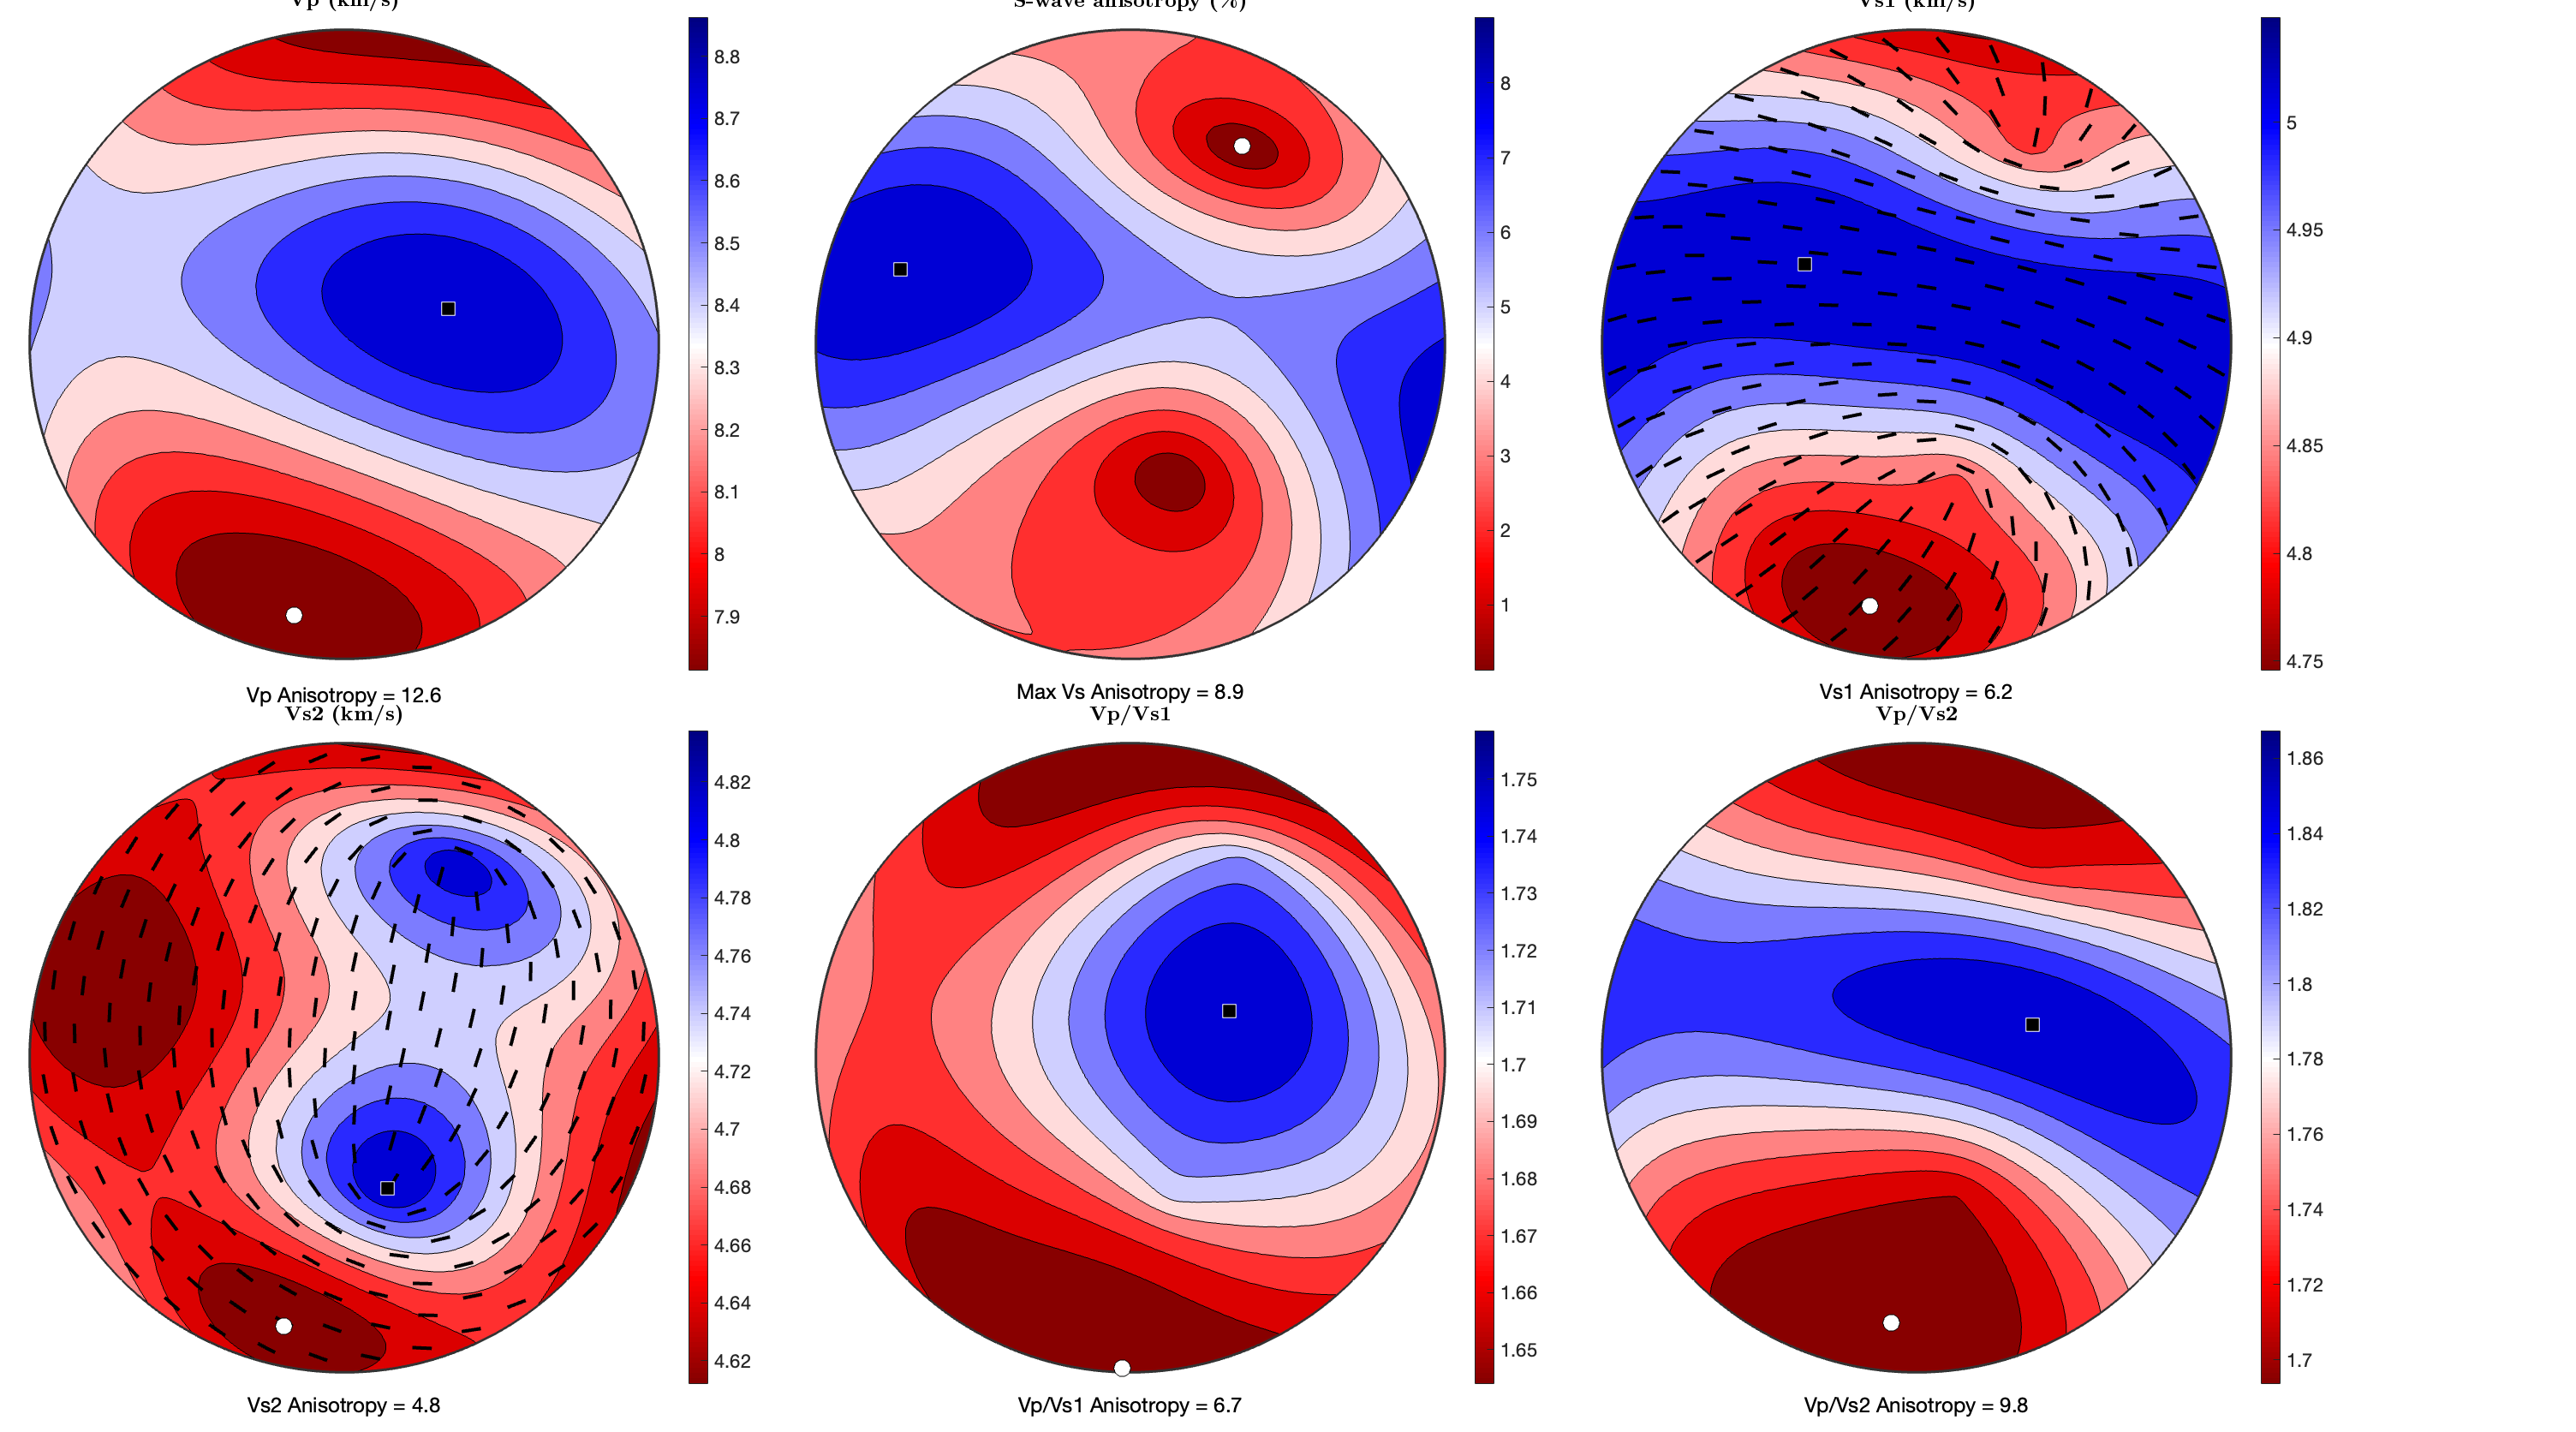

plotSeismicVelocities(CHill_ol)